# 034IN - FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL - A.Y. 2023-2024

# Full Examination - July 19 2024

# PART 2 - Design of a Controller 

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure

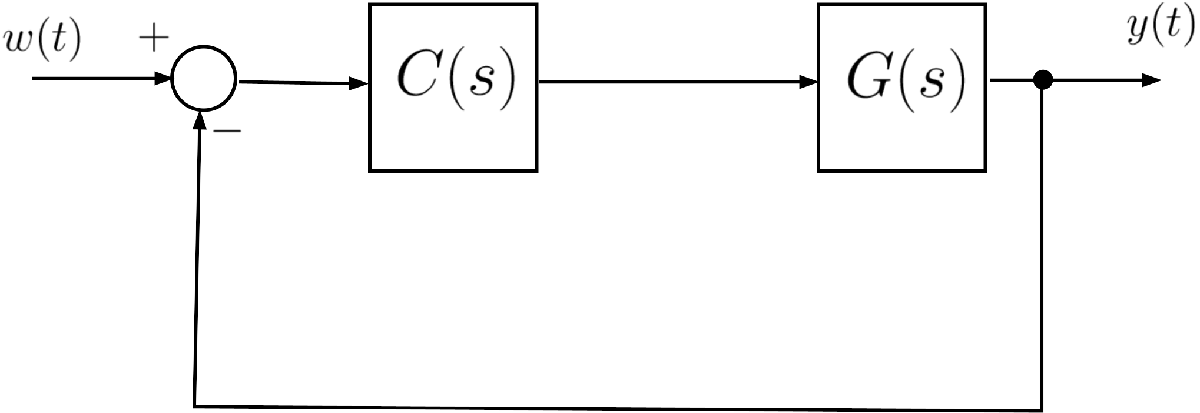	

where $G(s)$ is given by                


$$G(s) = \frac{4.8\,\left(1+0.01\,s\right)}{(1+0.25\,s)\,(1-25\,s)}$$


## **Question**		

**Q1**: Design a controller $C(s)$ such that all following requirements are simultaneously met: 

- The crossover angular frequency satisfies $\omega_c \ge 4.0\;\text{rad/s}$; 

- The phase margin satisfies $\varphi_m \ge 40^{\degree}$.

- $\left| e(\infty)\right| =0$ for $w(t) =  \mathbf{1}(t)$, where $\mathbf{1}(t)$ denotes the unit step function.

## Foreword to the Provided Solution

The proposed problem admits to more than one possible solution. The proposed solution is not the only admissible solution (in fact, the problem admits to infinite solutions), nor is it optimal. It is only a simple solution that can be obtained using the tools available in MATLAB's Control System Toolbox.

The present live script introduces up to five possible approaches to solving the design problem, giving complete insight into one of the proposals. Feel free to implement one of the other four proposals or a different design approach.

You are encouraged to solve the problem by finding alternative solutions and comparing the performance of the control system using your solution with those obtained using the proposed solution in this live script.  	

### A Practical Advise 	

The live script is very long, so the suggested practical approach is to analyse and execute the code section by section, using the commands `"Run Section"` or `"Run and Advance"`.

## Solution 

Since the system is open-loop unstable, the Bode stability criterion cannot be used in the way that is usual for the loop-shaping approach to the design of the controller for minimum-phase systems. Hence, as suggested in Example 3 in slides 41-44 of Part 10 of the lecture handouts, we use a **dual-loop control scheme**, as shown in the Figure below 

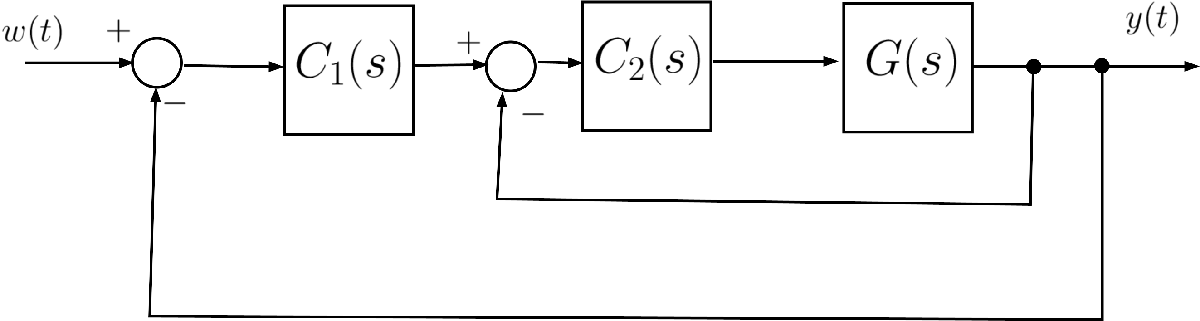

The design of the controller $C(s)$ is carried out by the following logical steps:

- The controller $C_2(s)$ is designed so as the **inner-loop transfer function **$F_2(s)$ from the output of the block $C_1(s)$ is **asymptotically** **stable**.

-  Subsequently, $C_1(s)$ will be designed to meet the other requirements.

% --- Live Script Initialisation ---
clear
close all
clc


% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))


### Step 1: Design of the Inner Loop Controller 

#### Preliminar Design exploiting the Root Locus

Let's define the transfer function of the process $G(s)$ and configure the MATLAB Search Path, by adding the folder containing the M-code able to compute and plot the asymptotic approximation of the Bode diagrams of the frequency response of a given transfer function.

% let's define the transfer function builder element
s=tf('s');

Gs = 4.8*(1+s/100)/((1+s/4)*(1-25*s)); % the unstable process G(s)


#### **The Inner Loop Controller: A Simple Proportional Gain**

To design the inner asymptotically-stable loop, the first attempt is to set


$$C_2(s) = \mu_2,\; \mu_2 \in \mathbb{R}$$


Let's explore the **Root** **Locus** of the **inner** **loop** **only**, looking for a feasible solution (i.e. by modifying only the gain constant of $C_2(s)$ am I able to stabilise the system?)

muC2 = 1; % first trial

C2s = tf(muC2); % the dynamic controller: a pure P gain

% let's compute the open-loop TF of the inner loop L2s
L2s = C2s*Gs;    % the open-loop TF
zL2 = zero(L2s);
pL2 = pole(L2s);

What if $\mu_2 >0$? Could the system be stabilised? Let's investigate on the Root Locus.

**Note**: due to the expression of $G(s)$, choosing $\mu_2>0$ means we are exploring the Inverse Root Locus of $L_2(s)$.


$$L_2(s) = \mu_2 \frac{4.8\,\left(1+0.01\,s\right)}{(1+0.25\,s)\,(1-25\,s)} \;
\Longrightarrow \; 
L_2(s) = -\frac{48\cdot 4}{10\cdot100\cdot 25} \mu_2 \frac{\left(s+100 \right)}{\left(s+4 \right)\, \left(s-\frac{1}{25} \right)} = \varrho  \frac{\left(s+100 \right)}{\left(s+4 \right)\, \left(s-\frac{1}{25} \right)}$$


Thus 


$$\mu_2>0 \, , \; \varrho = - \frac{24}{3125} \mu_2\; \Longrightarrow \; \varrho <0 \;\Longrightarrow \; 
1+\varrho \frac{(s+100)}{(s+4)\,\left(s-\frac{1}{25}\right)} = 0 \,,\; \varrho <0 \; \Longrightarrow \; \text{Inverse Root Locus}$$


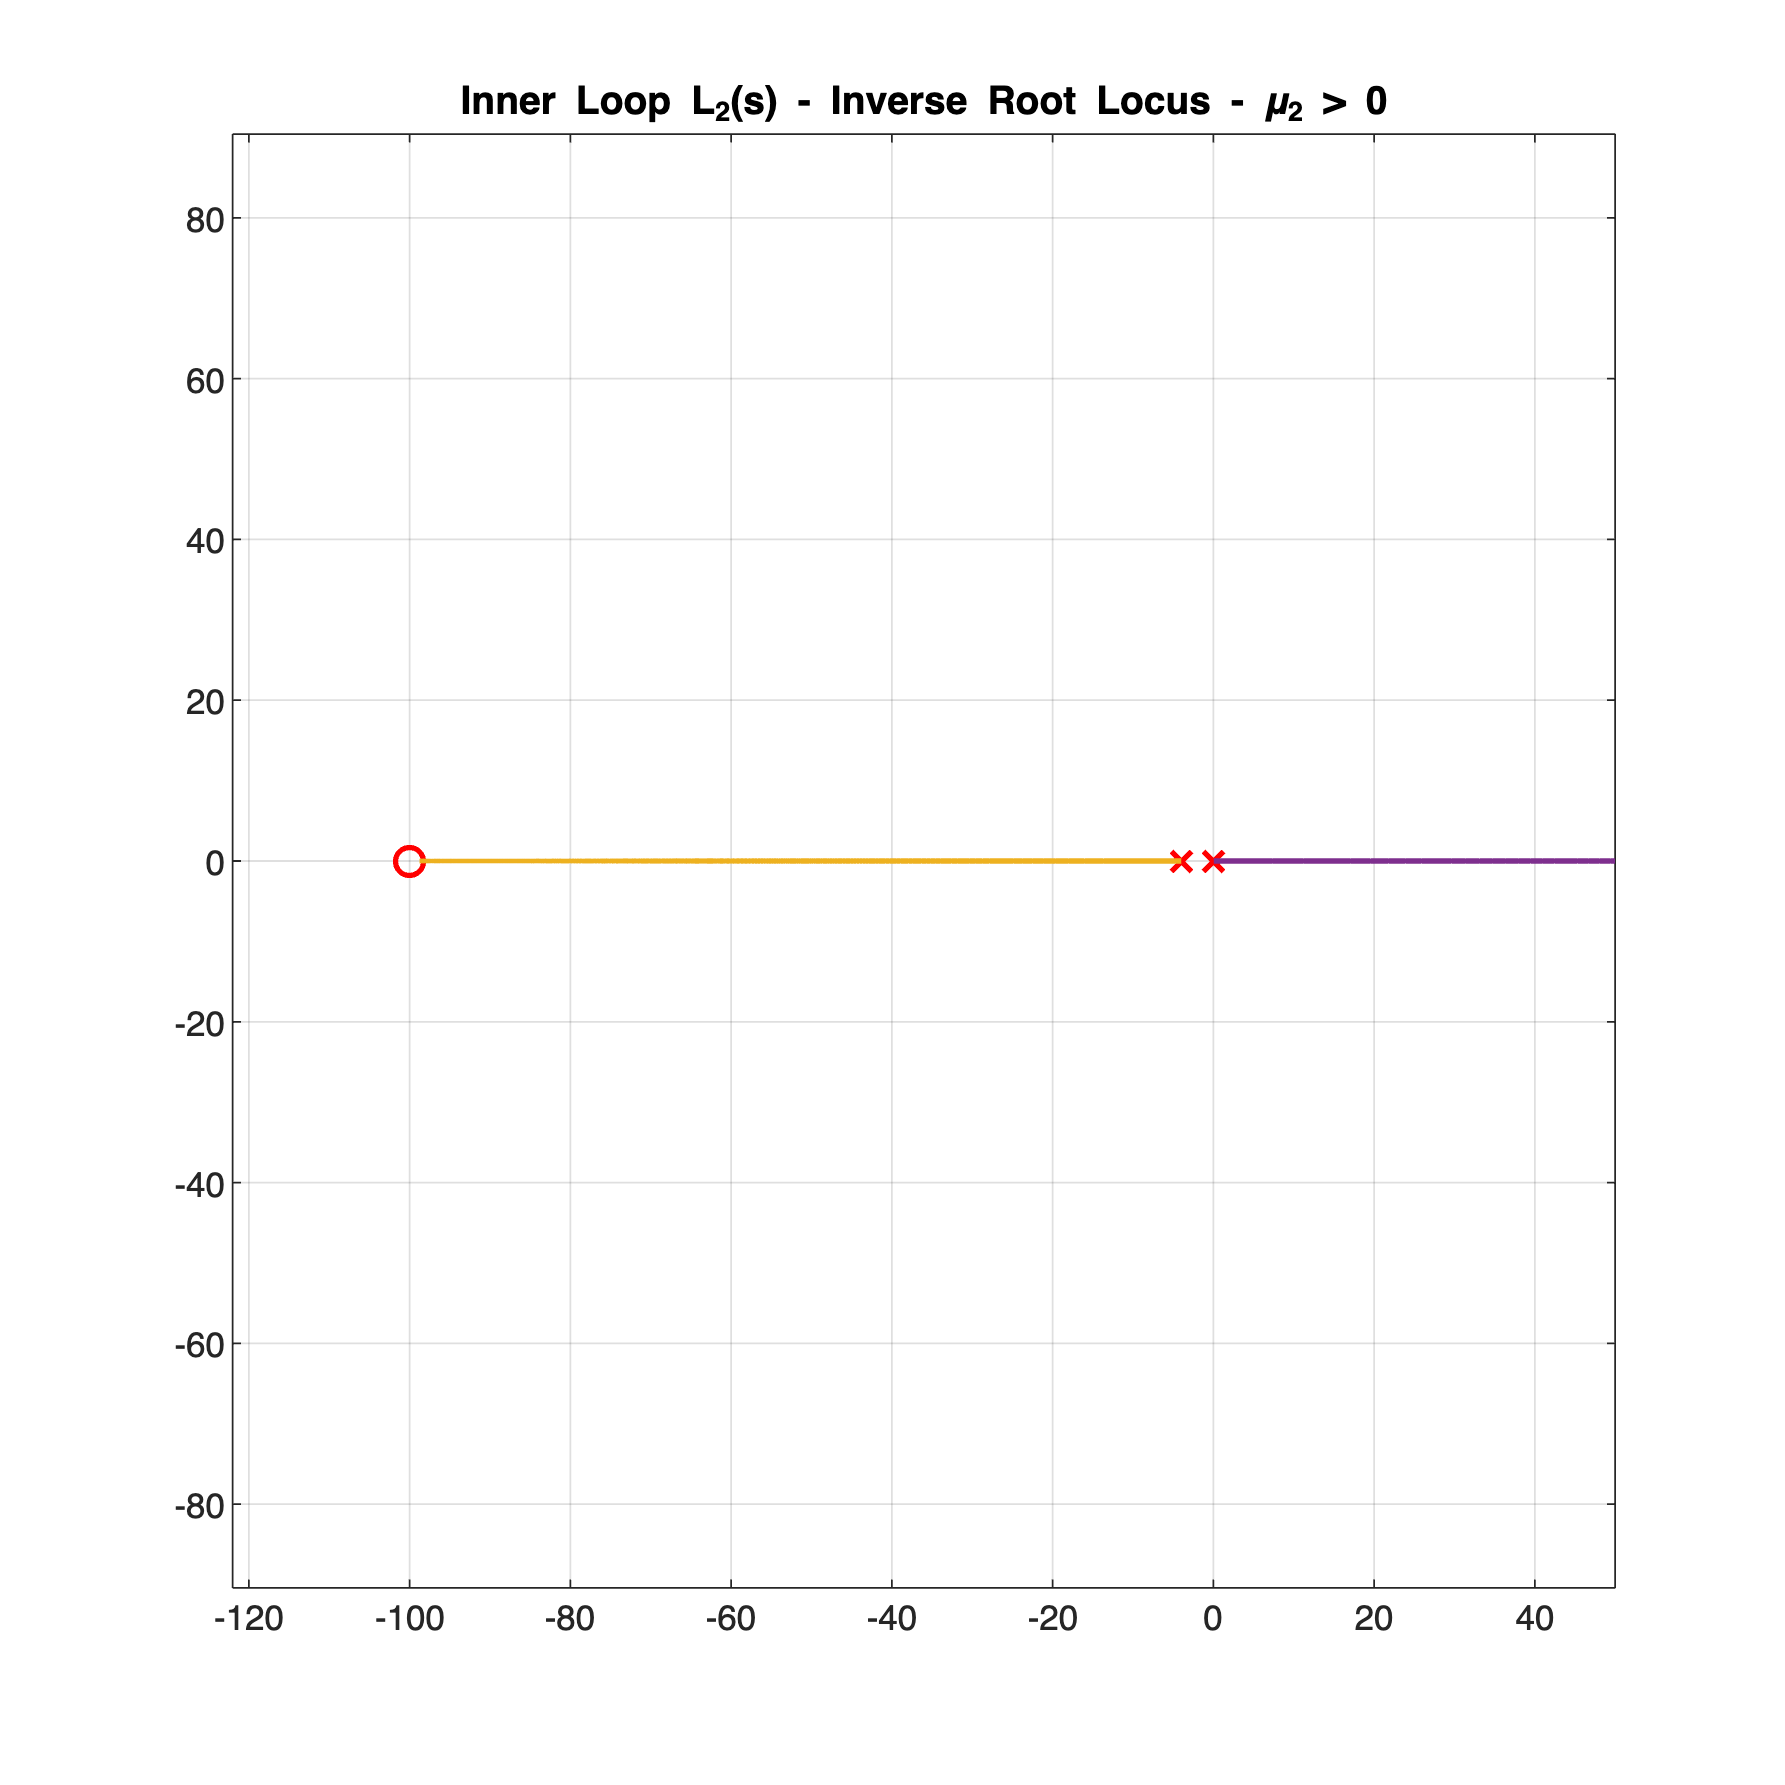

% --- exploring the Inverse Root Locus - the Inner Loop Transfer Funct. ---
mu2SET = linspace(0, 1e6, 1e4); 
% values for the gain mu2 > 0 to explore the Inverse RL
[IRL_L2, ~] = rlocus(L2s, mu2SET);

figure('Units','centimeters', 'Position',[0.1,0.1, 18, 18]);
% let's start with zeros & poles 
h_s1 = plot(real(zL2),imag(zL2),'ro', ...
    real(pL2),imag(pL2),'rx', ...
    'MarkerSize',8, 'LineWidth',1.5); 
hold on;
% L2s is a TF with only 1 zero and 2 pole, 
% so there are 2 singular points, 1 centroid,
% and 1 asymptote. We do not need centroid and/or singular points to
% perform the current analysis.

% the Inverse RL
for n=1:size(IRL_L2,1)
    h_rld1 = plot( real(IRL_L2(n,:)),imag(IRL_L2(n,:)), ...
               'LineWidth',1.5 );
end
grid on; hold off; axis equal;
zoom on; xlim([-122, +50]);
title('Inner Loop L_{2}(s) - Inverse Root Locus - \mu_{2} > 0');

**Using a positive gain** $\mu_2$ as simple inner controller $C_2(s)$, we **never stabilise** the inner-loop system. There is always an unstable pole belonging to the branch starting at the pole in $\bar p = +\frac{1}{25}$ and remaining entirely in the Right Half complex Plane (RHP).

What if $\mu_2 < 0$? 

**Note**: due to the expression of $G(s)$, choosing $\mu_2 < 0$ means we are exploring the Direct Root Locus of $L_2(s)$.


$$L_2(s) = \mu_2 \frac{4.8\,\left(1+0.01\,s\right)}{(1+0.25\,s)\,(1-25\,s)} \;
\Longrightarrow \; 
L_2(s) = -\frac{48\cdot 4}{10\cdot100\cdot 25} \mu_2 \frac{\left(s+100 \right)}{\left(s+4 \right)\, \left(s-\frac{1}{25} \right)} = \varrho  \frac{\left(s+100 \right)}{\left(s+4 \right)\, \left(s-\frac{1}{25} \right)}$$


Thus 


$$\mu_2<0 \, , \; \varrho = - \frac{24}{3125} \mu_2\; \Longrightarrow \; \varrho >0 \;\Longrightarrow \; 
1+\varrho \frac{(s+100)}{(s+4)\,\left(s-\frac{1}{25}\right)} = 0 \,,\; \varrho >0 \; \Longrightarrow \; \text{Direct Root Locus}$$


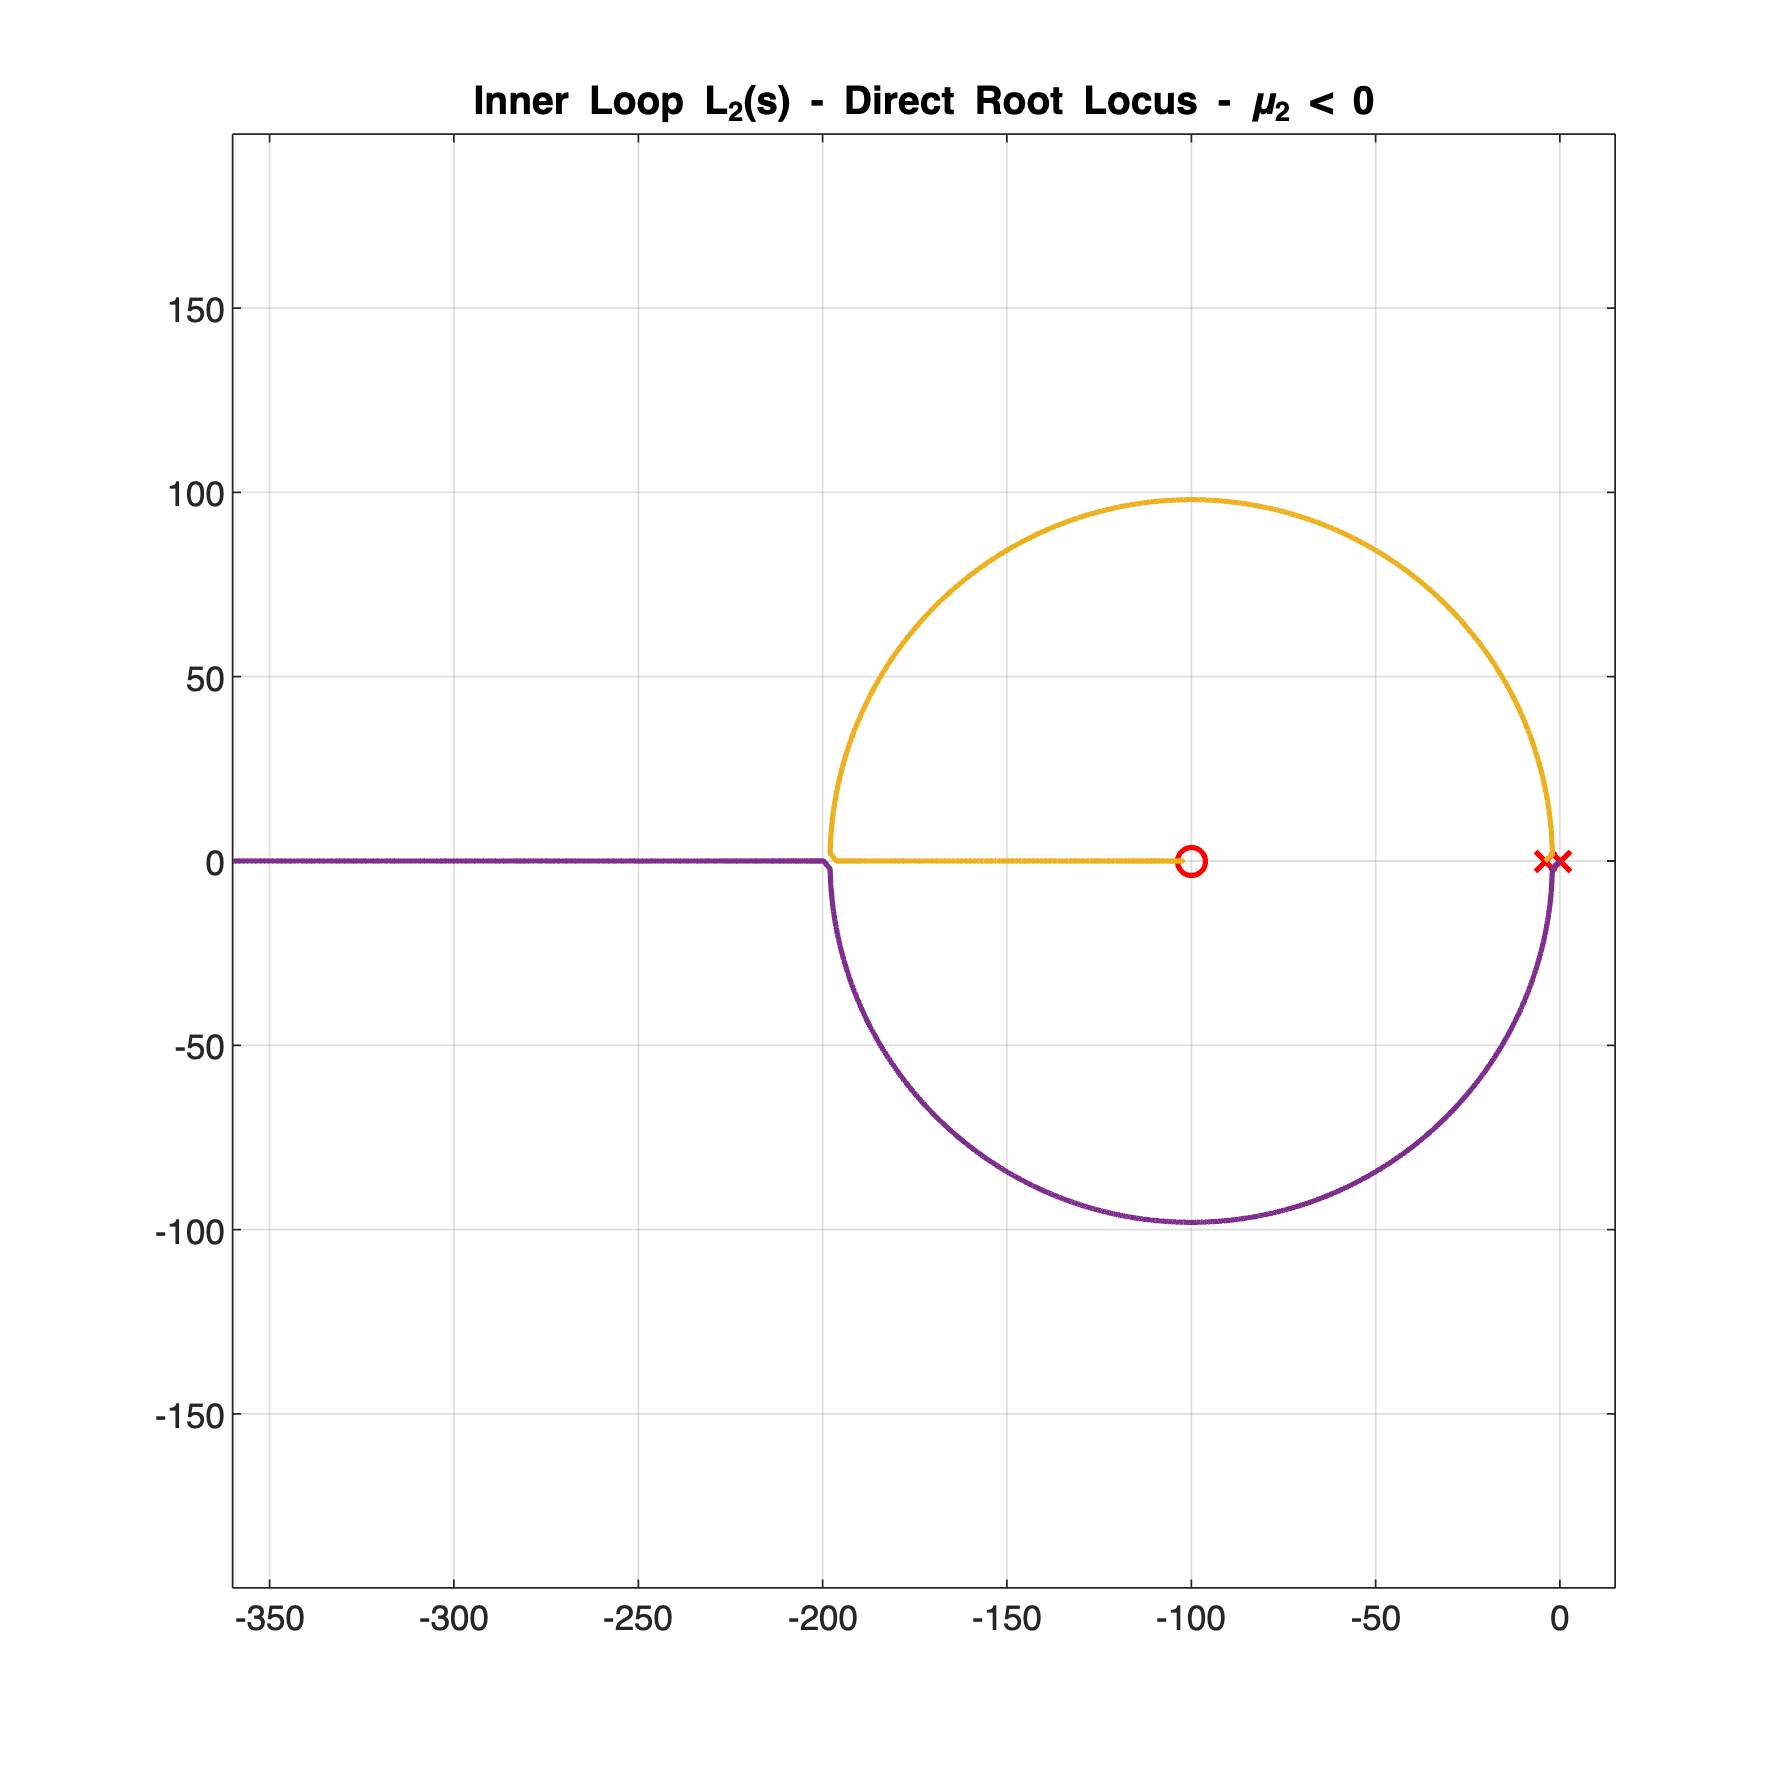

% --- exploring the Direct Root Locus - the Inner Loop Transfer Funct. ---
mu2SET = - linspace(0, 1e6, 1e5); 
% values for the gain mu2<0 to explore the Direct RL
[DRL_L2, ~] = rlocus(L2s, mu2SET);

figure('Units','centimeters', 'Position',[0.1,0.1, 18, 18]);
% let's start with zeros & poles 
h_s1 = plot(real(zL2),imag(zL2),'ro', ...
    real(pL2),imag(pL2),'rx', ...
    'MarkerSize',8, 'LineWidth',1.5); 
hold on;
% L2s is a TF with only 1 zero and 2 pole, 
% so there are 2 singular points, 1 centroid,
% and 1 asymptote. We do not need centroid and/or singular points to
% perform the current analysis.

% the Direct RL
for n=1:size(DRL_L2,1)
    h_rld1 = plot( real(DRL_L2(n,:)),imag(DRL_L2(n,:)), ...
               'LineWidth',1.5 );
end
grid on; hold off; 
axis equal; zoom on;  xlim([-360, +15]);
title('Inner Loop L_{2}(s) - Direct Root Locus - \mu_{2} < 0');

**Remark**: Choosing an appropriate negative value for the gain $\mu_2$ stabilises the internal loop with the transfer function $L_2(s)$.

#### The Choice of the Controller Gain: Analysis on the Root Locus

How do we choose an appropriate value for the gain $\mu_2$?

Let's analyse a few values for the gain $\mu_2$: what if $\mu_2$ holds $-6$, $-60$, $-600$ or $-1200$?

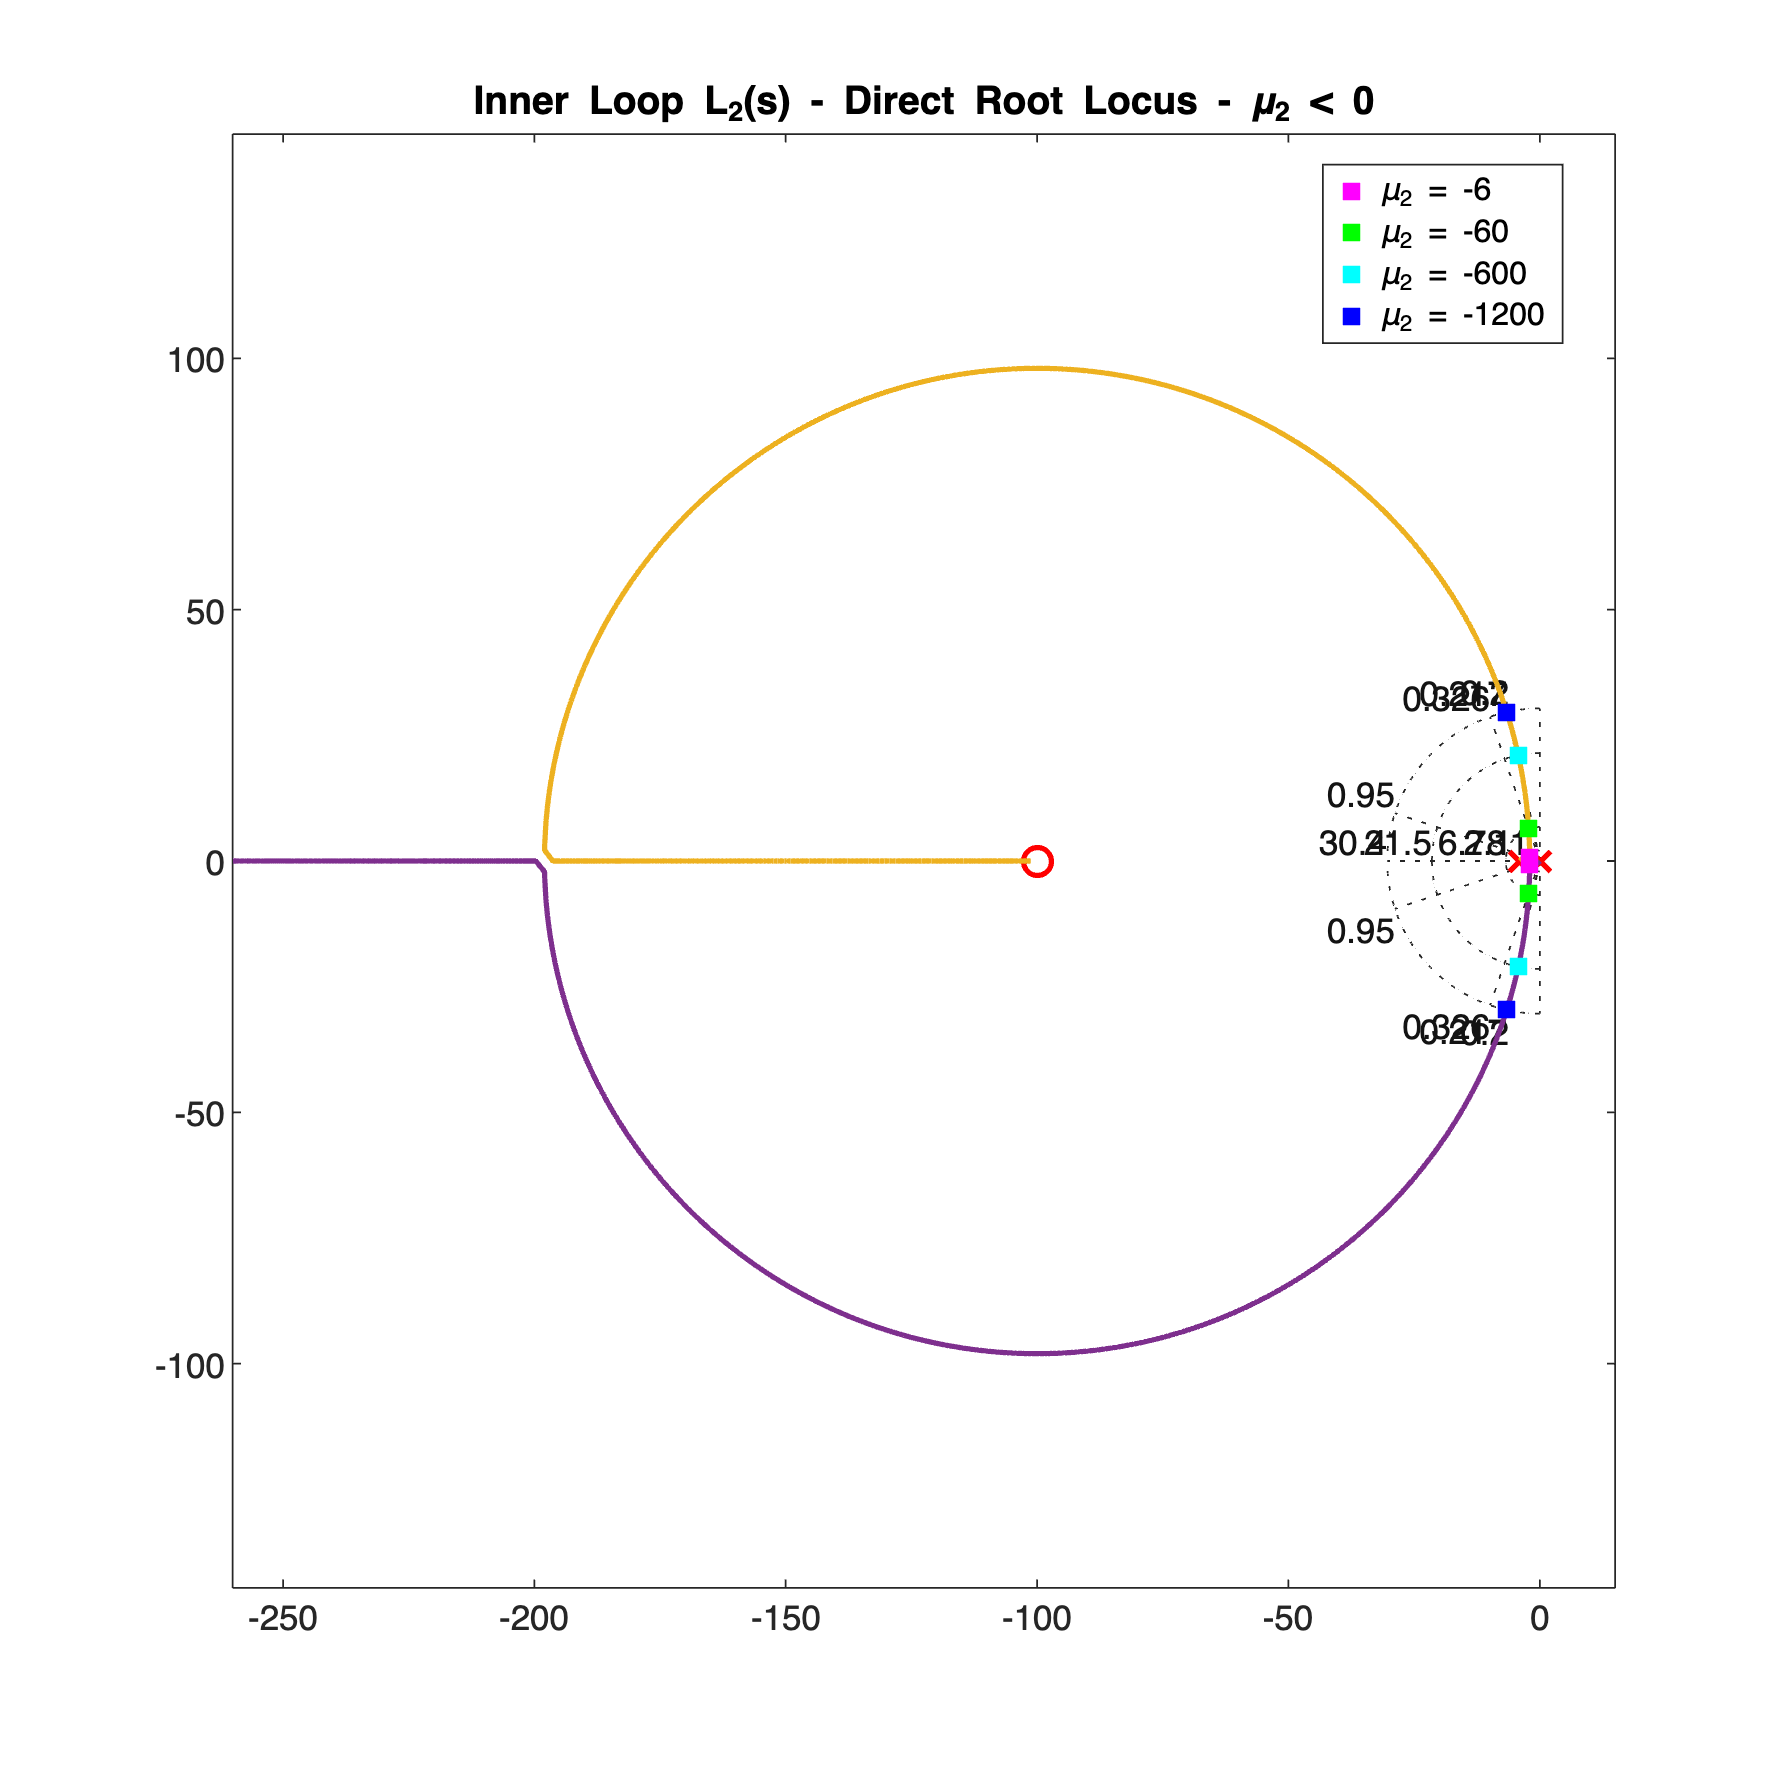

% --- exploring the Direct Root Locus - the Inner Loop Transfer Funct. ---
mu2SET = - linspace(0, 1e6, 1e5); 
% values for the gain mu2<0 to draw the Direct RL
[DRL_L2, ~] = rlocus(L2s, mu2SET);

mu2_TRIAL = [-6, -60, -600, -1200]; % <-- possible choices for mu2

figure('Units','centimeters', 'Position',[0.1,0.1, 18, 18]);
% let's start with zeros & poles 
h_s1 = plot(real(zL2),imag(zL2),'ro', ...
    real(pL2),imag(pL2),'rx', ...
    'MarkerSize',8, 'LineWidth',1.5); 
hold on;
% let's sketch the Direct RL
for n=1:size(DRL_L2,1)
    plot( real(DRL_L2(n,:)),imag(DRL_L2(n,:)), ...
               'LineWidth',1.5 );
end

axis equal; zoom on;  xlim([-260, +15]);
title('Inner Loop L_{2}(s) - Direct Root Locus - \mu_{2} < 0');

% --- --- --- --- --- --- --- --- --- --- --- --- --- --- --- ---
% now superimpose the position of the closed-loop poles corresponding
% to the three possible choices of mu2 in the set mu2_TRIAL
hold on;
[TRIAL_L2, ~] = rlocus(L2s, mu2_TRIAL); % <-- let's evaluate 
                                        %     the closed-loop poles
                                        %     corresponding to the three
                                        %     chosen gain values

MarkColors = ['m', 'g', 'c', 'b', 'y', 'k', 'r']; % marker color
pM = [];
for n=1:size(TRIAL_L2,2)
   hM = plot( real(TRIAL_L2(:,n)),imag(TRIAL_L2(:,n)), ...
               'Marker','square',...
               'MarkerEdgeColor',MarkColors(n),...
               'MarkerFaceColor',MarkColors(n),...
               'MarkerSize', 6,...
               'LineStyle','none');
   pM = [pM, hM];
end

OmegaN_mu2 = abs(TRIAL_L2); % the natural ang. frequencies 
                            % corresponding to each couple of poles
DampF_mu2 = abs(real(TRIAL_L2))./ abs(TRIAL_L2); % the damping factor associated
                                                 % to each couple of poles

% let's draw a grid on the root locus, with constant damping ratio (DampF_mu2)
% and natural frequency (OmegaN_mu2)
sgrid(DampF_mu2(1,:), OmegaN_mu2(1,:)); 
legend(pM,['\mu_2 = ',num2str(mu2_TRIAL(1))],...
         ['\mu_2 = ',num2str(mu2_TRIAL(2))], ...
         ['\mu_2 = ',num2str(mu2_TRIAL(3))],...
         ['\mu_2 = ',num2str(mu2_TRIAL(4))], 'Location','best')

**Remark 1**: by decreasing the value of $\mu_2$, the natural frequency of the couple of poles increases, and the damping factor decreases. Moreover, due to the low damping factor in the scenarios with $\mu_2 = -60,\, -600$ and $\mu_2=-1200$, the **magnitude** of the frequency response will have a **resonance peak** at the natural frequency of the poles. This peak is higher as the damping factor decreases. 

**Remark 2**: the transfer function $L_2(s)$ has $2$ poles and $1$ zero and so also the corresponding closed loop transfer function $F_2(s)$. The knowledge of the closed loop poles of $F_2(s)$ from the root locus does allow us only to evaluate an approximation of the effective $F_2(s)$ cross-over frequency $\omega_{c\,2}$, due to the zero in the transfer function $F_2(s)$. 

#### The Choice of the Controller Gain: Analysis on the Bode Diagrams

Let's analyse the Bode diagrams of the frequency response of each possible closed loop transfer function $F_2(s)$, putting in evidence the required crossover frequency $\omega_{c\,1}$ and the requirement on the frequency response phase for $F_2(j \omega)$, taking into account the outer control loop, with the controller $C_1(s)$:

- according to the requirement Q1.3, the outer controller $C_1(s)$ must have an integral control action term: $C_1(s) = \frac{\mu_1}{s}$

- fulfilling requirement Q1.1 implies that $\omega_{c\,1} \ge \bar \omega = 4 \; \text{rad/s}$, where $\omega_{c\,1}$ is the crossover angular frequency;

- taking into account the integral control term in $C_1(s)$, the requirement Q1.2 on the phase margin becomes the following constraint on the frequency response phase of $L_1(s) = C_1(s) \cdot F_2(s)$: $\arg L_1(j \omega) \ge -140^{\circ}$ [the worst case, supposing to apply a pure integral action for the controller $C_1(s)$] .

barOmega = 4.00; % crossover freq. for the outer closed loop
                 % according to the requirement Q1.1
Ph_Constraint = -140; % the worst case scenario allowed phase for L1(j*omega), when
                     % omega >= barOmega (req. Q1.2)


% let's evaluate the inner closed loop transfer function F2(s)
% corresponding to each candidate gain mu2
F2s_1 = feedback(mu2_TRIAL(1)*Gs, 1, -1);
F2s_2 = feedback(mu2_TRIAL(2)*Gs, 1, -1);
F2s_3 = feedback(mu2_TRIAL(3)*Gs, 1, -1);
F2s_4 = feedback(mu2_TRIAL(4)*Gs, 1, -1);

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams


**The First Scenario: **$\mathbf{\mu_2 = -6}$

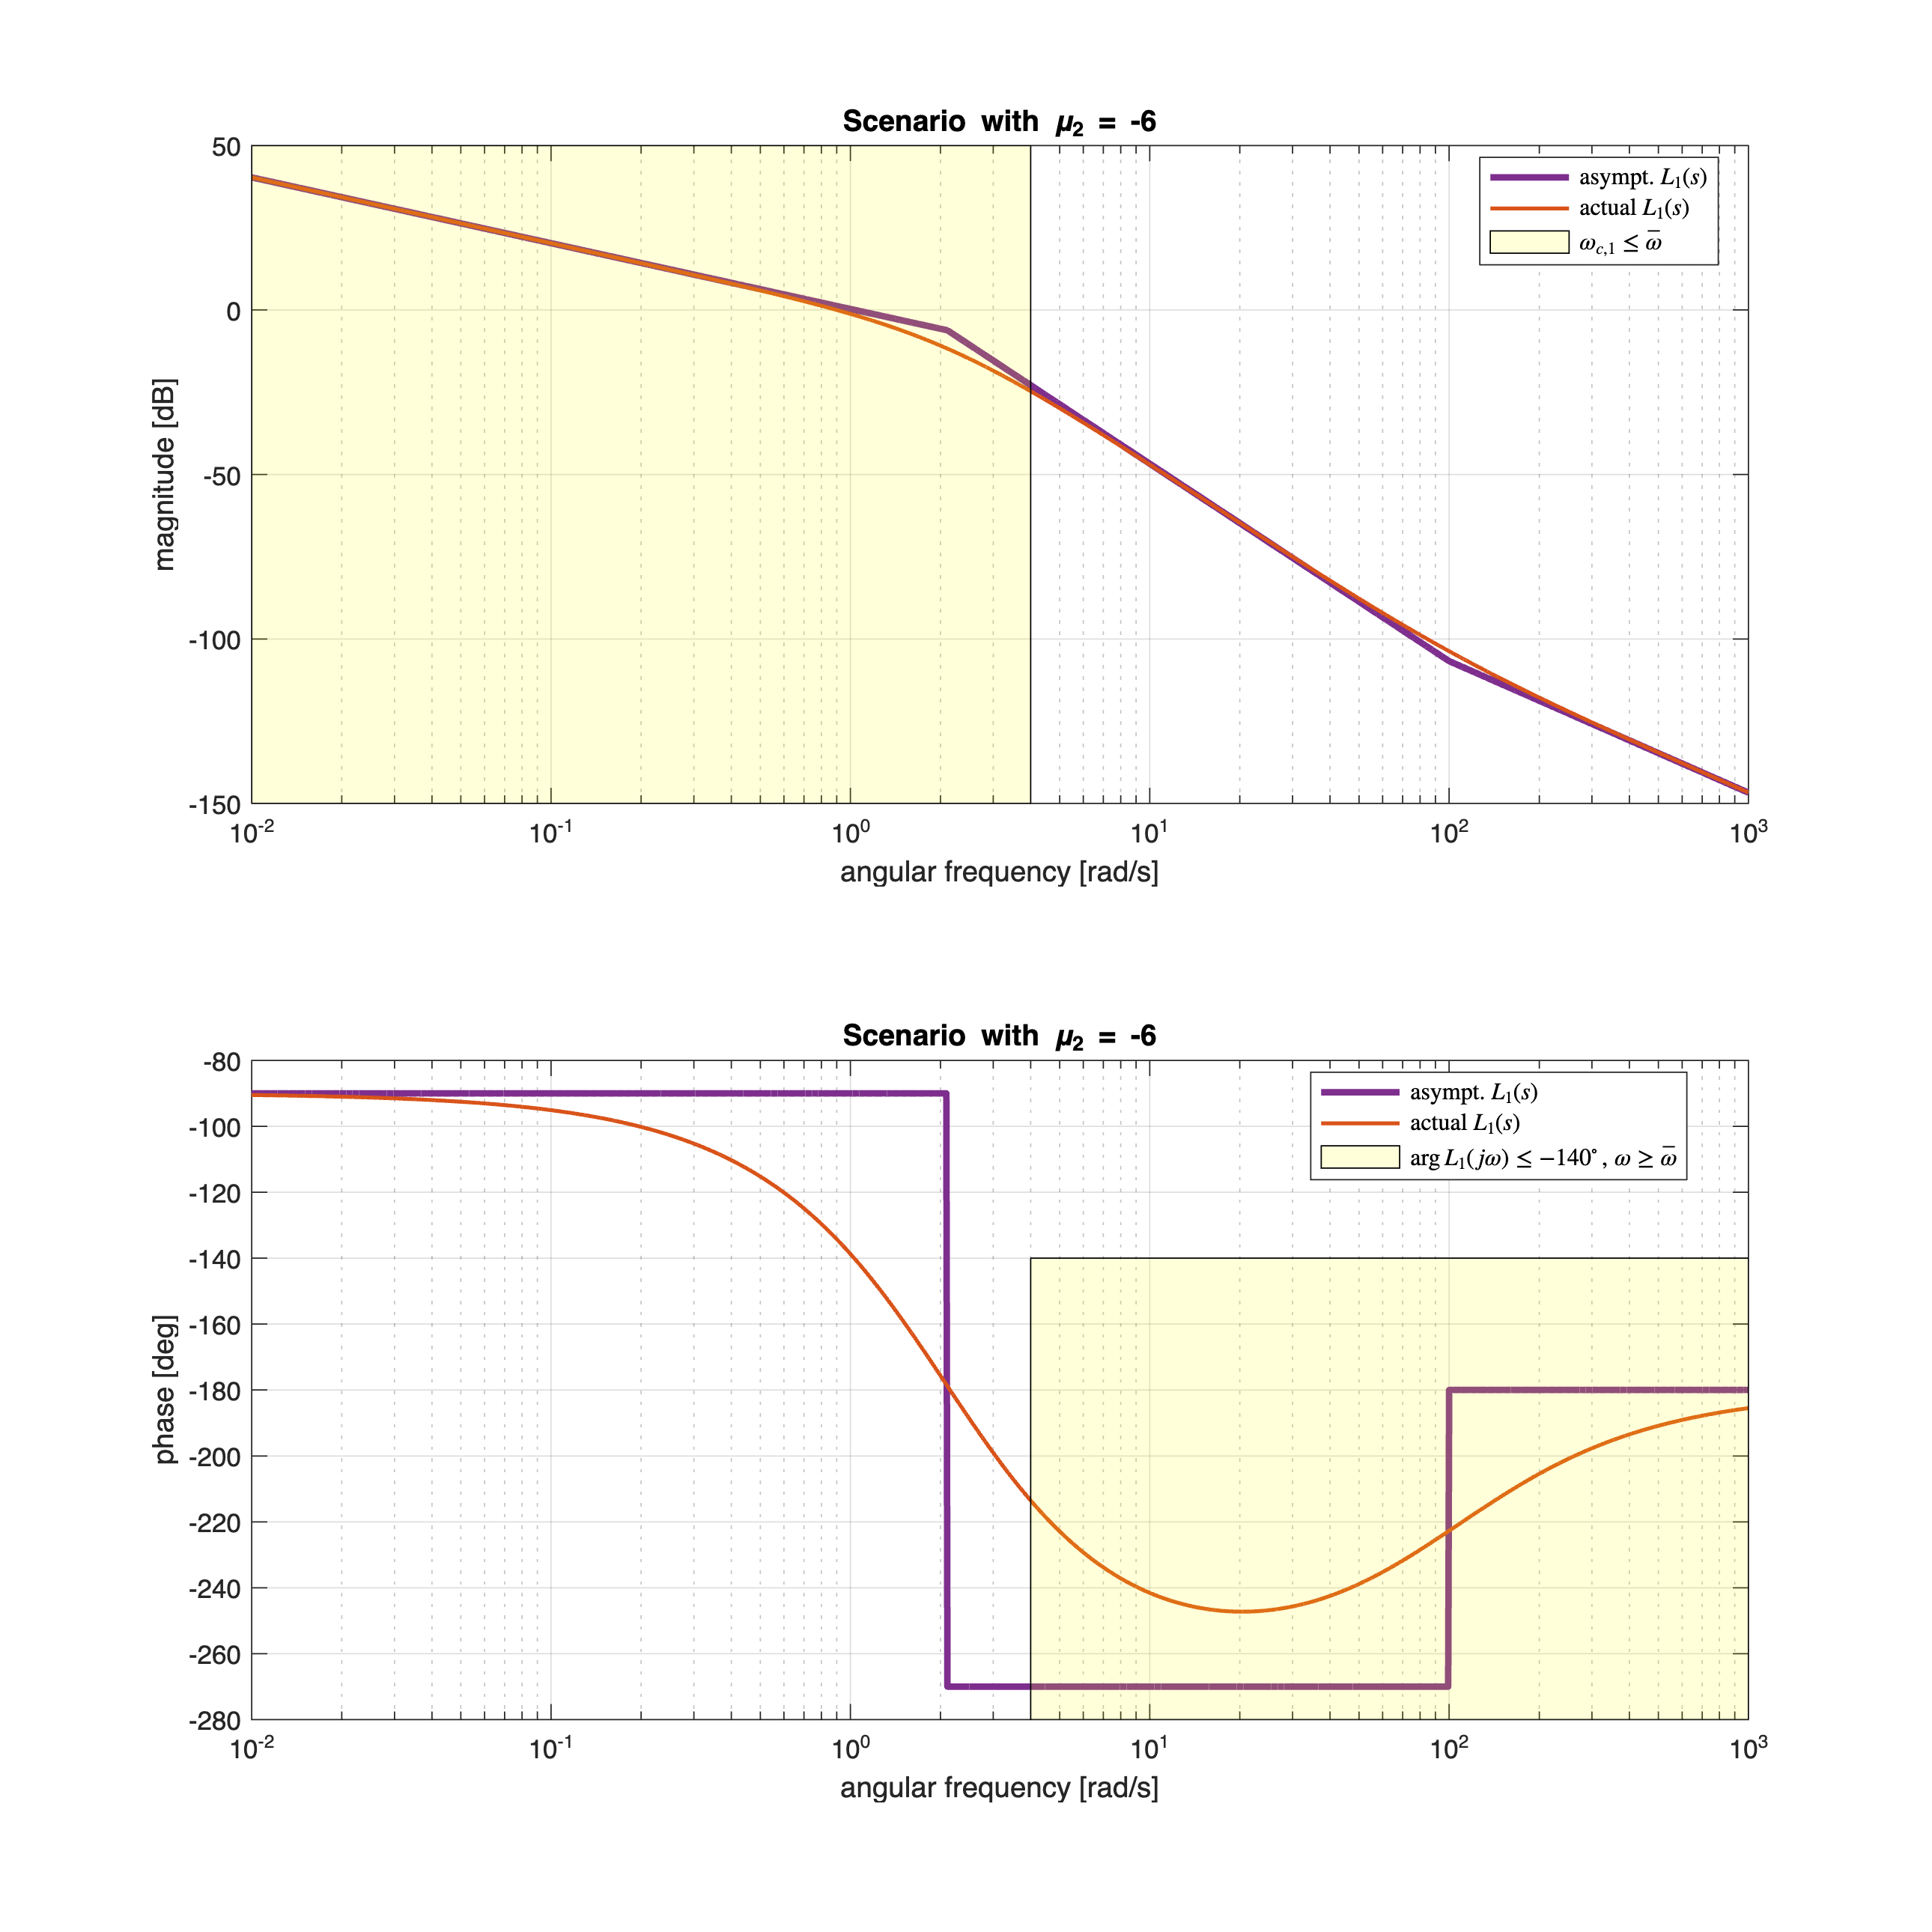

% --- 1st case: mu2 = -6 ---
hf1 = figure('Units','centimeters', 'Position',[0.1,0.1, 26, 26]);

C1s = 1/s; % simply the integral control action

L1_s = C1s*F2s_1; % <-- the open-loot transfer function for the outer loop

omVALS = logspace(-2, 3, 1e5); % ang. freqs in [1/100; 1000]
[hax1, hax2] = drawBodediagrams(L1_s, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hf1);

rLimOmega = min(xlim(hax1)); % the minimum value of the ang. frequency in the drawing
Yl = ylim(hax1); % the minimum and the maximum values of the frequency response
                 % magnitude in the drawing

Vert1 = [barOmega Yl(1); barOmega Yl(2); rLimOmega Yl(1); rLimOmega Yl(2)];
Faces1 = [1  2  4  3];
patch(hax1, 'Faces',Faces1,'Vertices',Vert1,'FaceColor','yellow','FaceAlpha',.15);

rLimOmega = max(xlim(hax2)); % the maximum value of the ang. frequency in the drawing
PH_Yl = ylim(hax2); % the minimum and the maximum values of the frequency response
                 % phase in the drawing
Vert2 = [barOmega min(PH_Yl); barOmega min(Ph_Constraint, max(PH_Yl));...
         rLimOmega min(PH_Yl); rLimOmega min(Ph_Constraint, max(PH_Yl))];
Faces2 = [1  2  4  3];
patch(hax2, 'Faces',Faces2,'Vertices',Vert2,'FaceColor','yellow','FaceAlpha',.15);

title(hax1, ['Scenario with \mu_2 = ', num2str(mu2_TRIAL(1))]);
title(hax2, ['Scenario with \mu_2 = ', num2str(mu2_TRIAL(1))]);

legend(hax1,  'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
             ' $\omega_{c,1} \le \bar{\omega}$','Location', 'best', ...
             'Interpreter', 'latex');
legend(hax2,  'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
             '$\arg L_1(j \omega) \le -140^{\circ}\,,\; \omega \ge \bar{\omega}$',...
             'Location', 'best', 'Interpreter', 'latex');

**Remark**: The pale yellow regions correspond to the forbidden zones, respectively for the crossover angular frequency $\omega_{c\,1}$ and for the frequency response phase $\arg L_1(j \omega)$. 

- Note: to obtain a crossover frequency $\omega_{c\,1}$ fulfilling the requirement Q1.3, you should increase the gain constant $\mu_1$.

- For $\omega \ge 4 \; \text{rad/s}$, the frequency response phase $\arg L_1(j \omega)$ is not fulfilling the constraint. 

- Applying a simple integral control action in $C_1(s)$ does not fulfil all the requirements.

-  In particular, the required phase margin can be obtained only by adding at least one zero to the controller transfer function.

**The Second Scenario: **$\mathbf{\mu_2 = -60}$

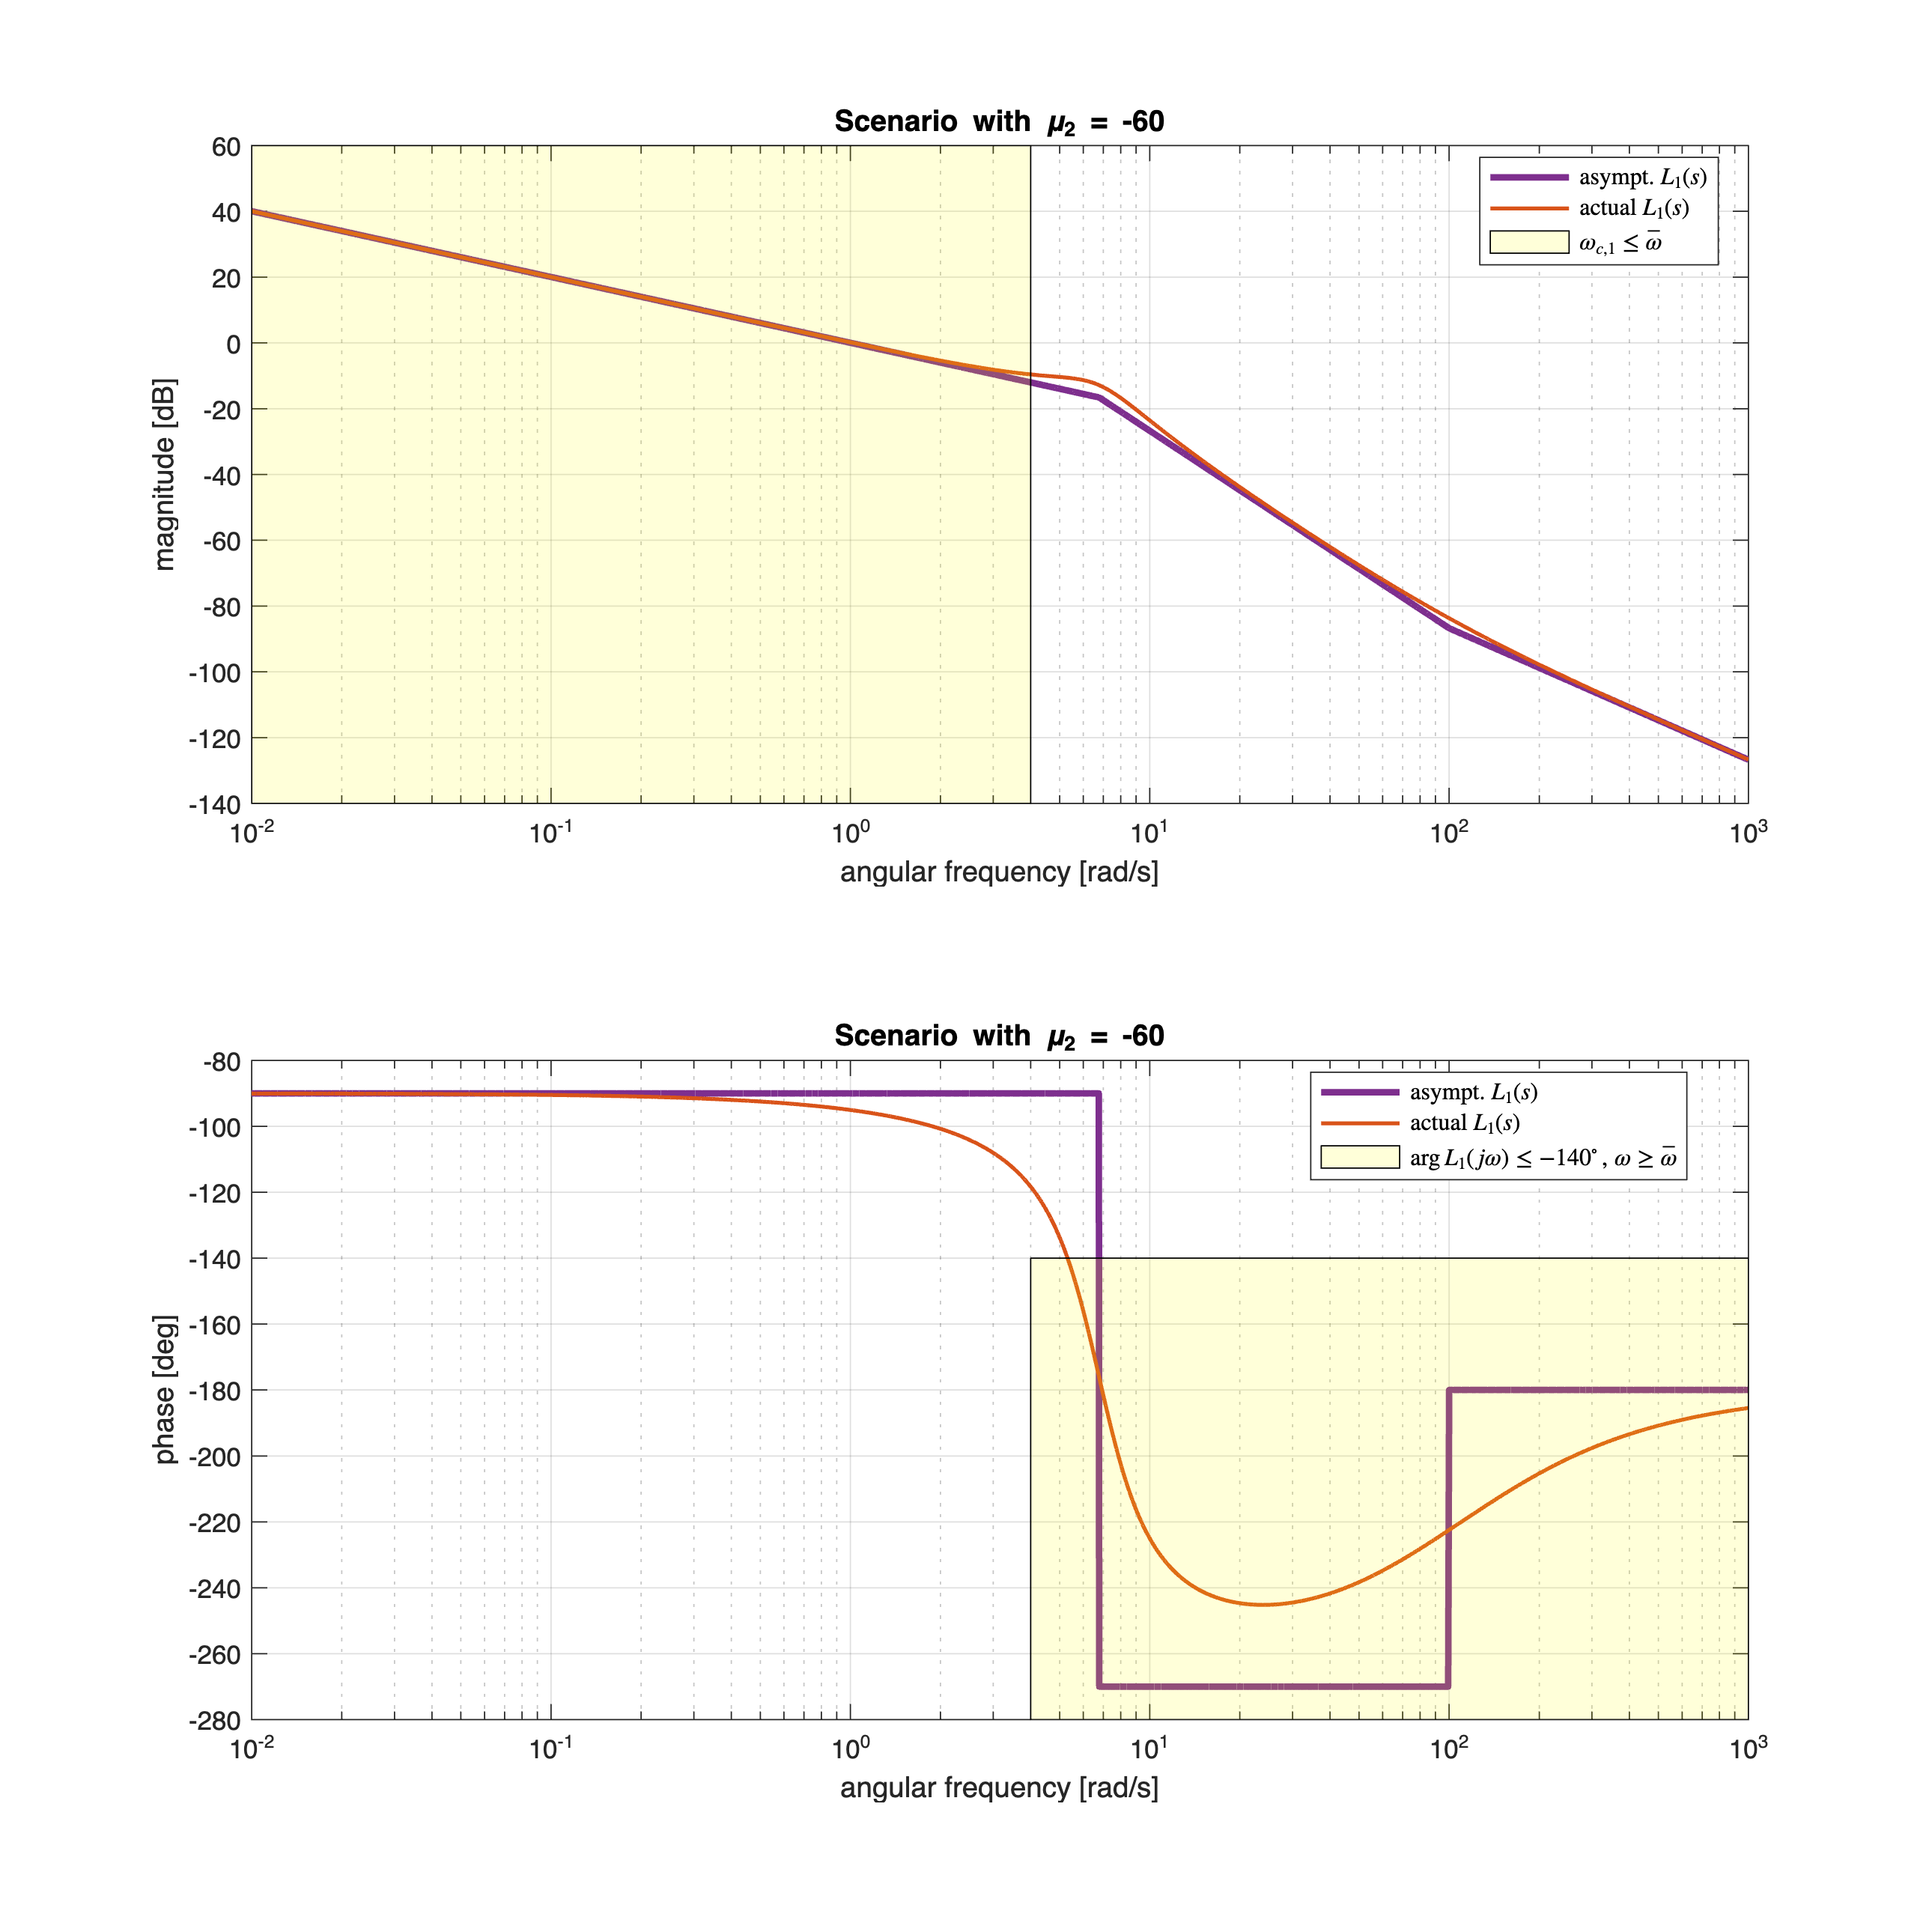

% --- 2nd case: mu2 = -60 ---
hf2 = figure('Units','centimeters', 'Position',[0.1,0.1, 26, 26]);

L1_s = C1s*F2s_2; % <-- the open-loot transfer function for the outer loop

omVALS = logspace(-2, 3, 1e5); % ang. freqs in [1/100; 1000]
[hax1, hax2] = drawBodediagrams(L1_s, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hf2);

rLimOmega = min(xlim(hax1)); % the minimum value of the ang. frequency in the drawing
Yl = ylim(hax1); % the minimum and the maximum values of the frequency response
                 % magnitude in the drawing

Vert1 = [barOmega Yl(1); barOmega Yl(2); rLimOmega Yl(1); rLimOmega Yl(2)];
Faces1 = [1  2  4  3];
patch(hax1, 'Faces',Faces1,'Vertices',Vert1,'FaceColor','yellow','FaceAlpha',.15);

rLimOmega = max(xlim(hax2)); % the maximum value of the ang. frequency in the drawing
PH_Yl = ylim(hax2); % the minimum and the maximum values of the frequency response
                 % phase in the drawing
Vert2 = [barOmega min(PH_Yl); barOmega min(Ph_Constraint, max(PH_Yl));...
         rLimOmega min(PH_Yl); rLimOmega min(Ph_Constraint, max(PH_Yl))];
Faces2 = [1  2  4  3];
patch(hax2, 'Faces',Faces2,'Vertices',Vert2,'FaceColor','yellow','FaceAlpha',.15);

title(hax1, ['Scenario with \mu_2 = ', num2str(mu2_TRIAL(2))]);
title(hax2, ['Scenario with \mu_2 = ', num2str(mu2_TRIAL(2))]);

legend(hax1,  'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
             ' $\omega_{c,1} \le \bar{\omega}$','Location', 'best', ...
             'Interpreter', 'latex');
legend(hax2,  'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
             '$\arg L_1(j \omega) \le -140^{\circ}\,,\; \omega \ge \bar{\omega}$',...
             'Location', 'best', 'Interpreter', 'latex');

**Remark**: The pale yellow regions correspond to the forbidden zones, respectively for the crossover angular frequency $\omega_{c\,1}$ and for the frequency response phase $\arg L_1(j \omega)$. 

- Note: to obtain a crossover frequency $\omega_{c\,1}$ fulfilling the requirement Q1.3, you should increase the gain constant $\mu_1$.

- For $\omega = 4 \; \text{rad/s}$, the frequency response phase $\arg L_1(j \omega)$ is  fulfilling the constraint. 

- Applying a simple integral control action in $C_1(s)$ could fulfil all the requirements. 

- Pay attention to the **resonance peak** in the frequency response **magnitude** diagram. Note how the **phase margin quickly drops** when the angular frequency $\omega$ is increasing from $4$ to $5\; \text{rad/s}$.

-  If you would obtain $\omega_{c\,1} \ge 5$, the required phase margin can be obtained  by adding one zero to the controller transfer function.

- To keep the design as easy as possible, you should design an integral controller imposing $\omega = 4\;\text{rad/s}$ as the crossover frequency $\omega_{c\,1}$and tuning the gain $\mu_1$properly: due to the resonance peak in the magnitude response, you may guess a gain value lower than $4$( for fine tuning, you should use the `controlSystemDesigner` App).

**The Third Scenario: **$\mathbf{\mu_2 = -600}$

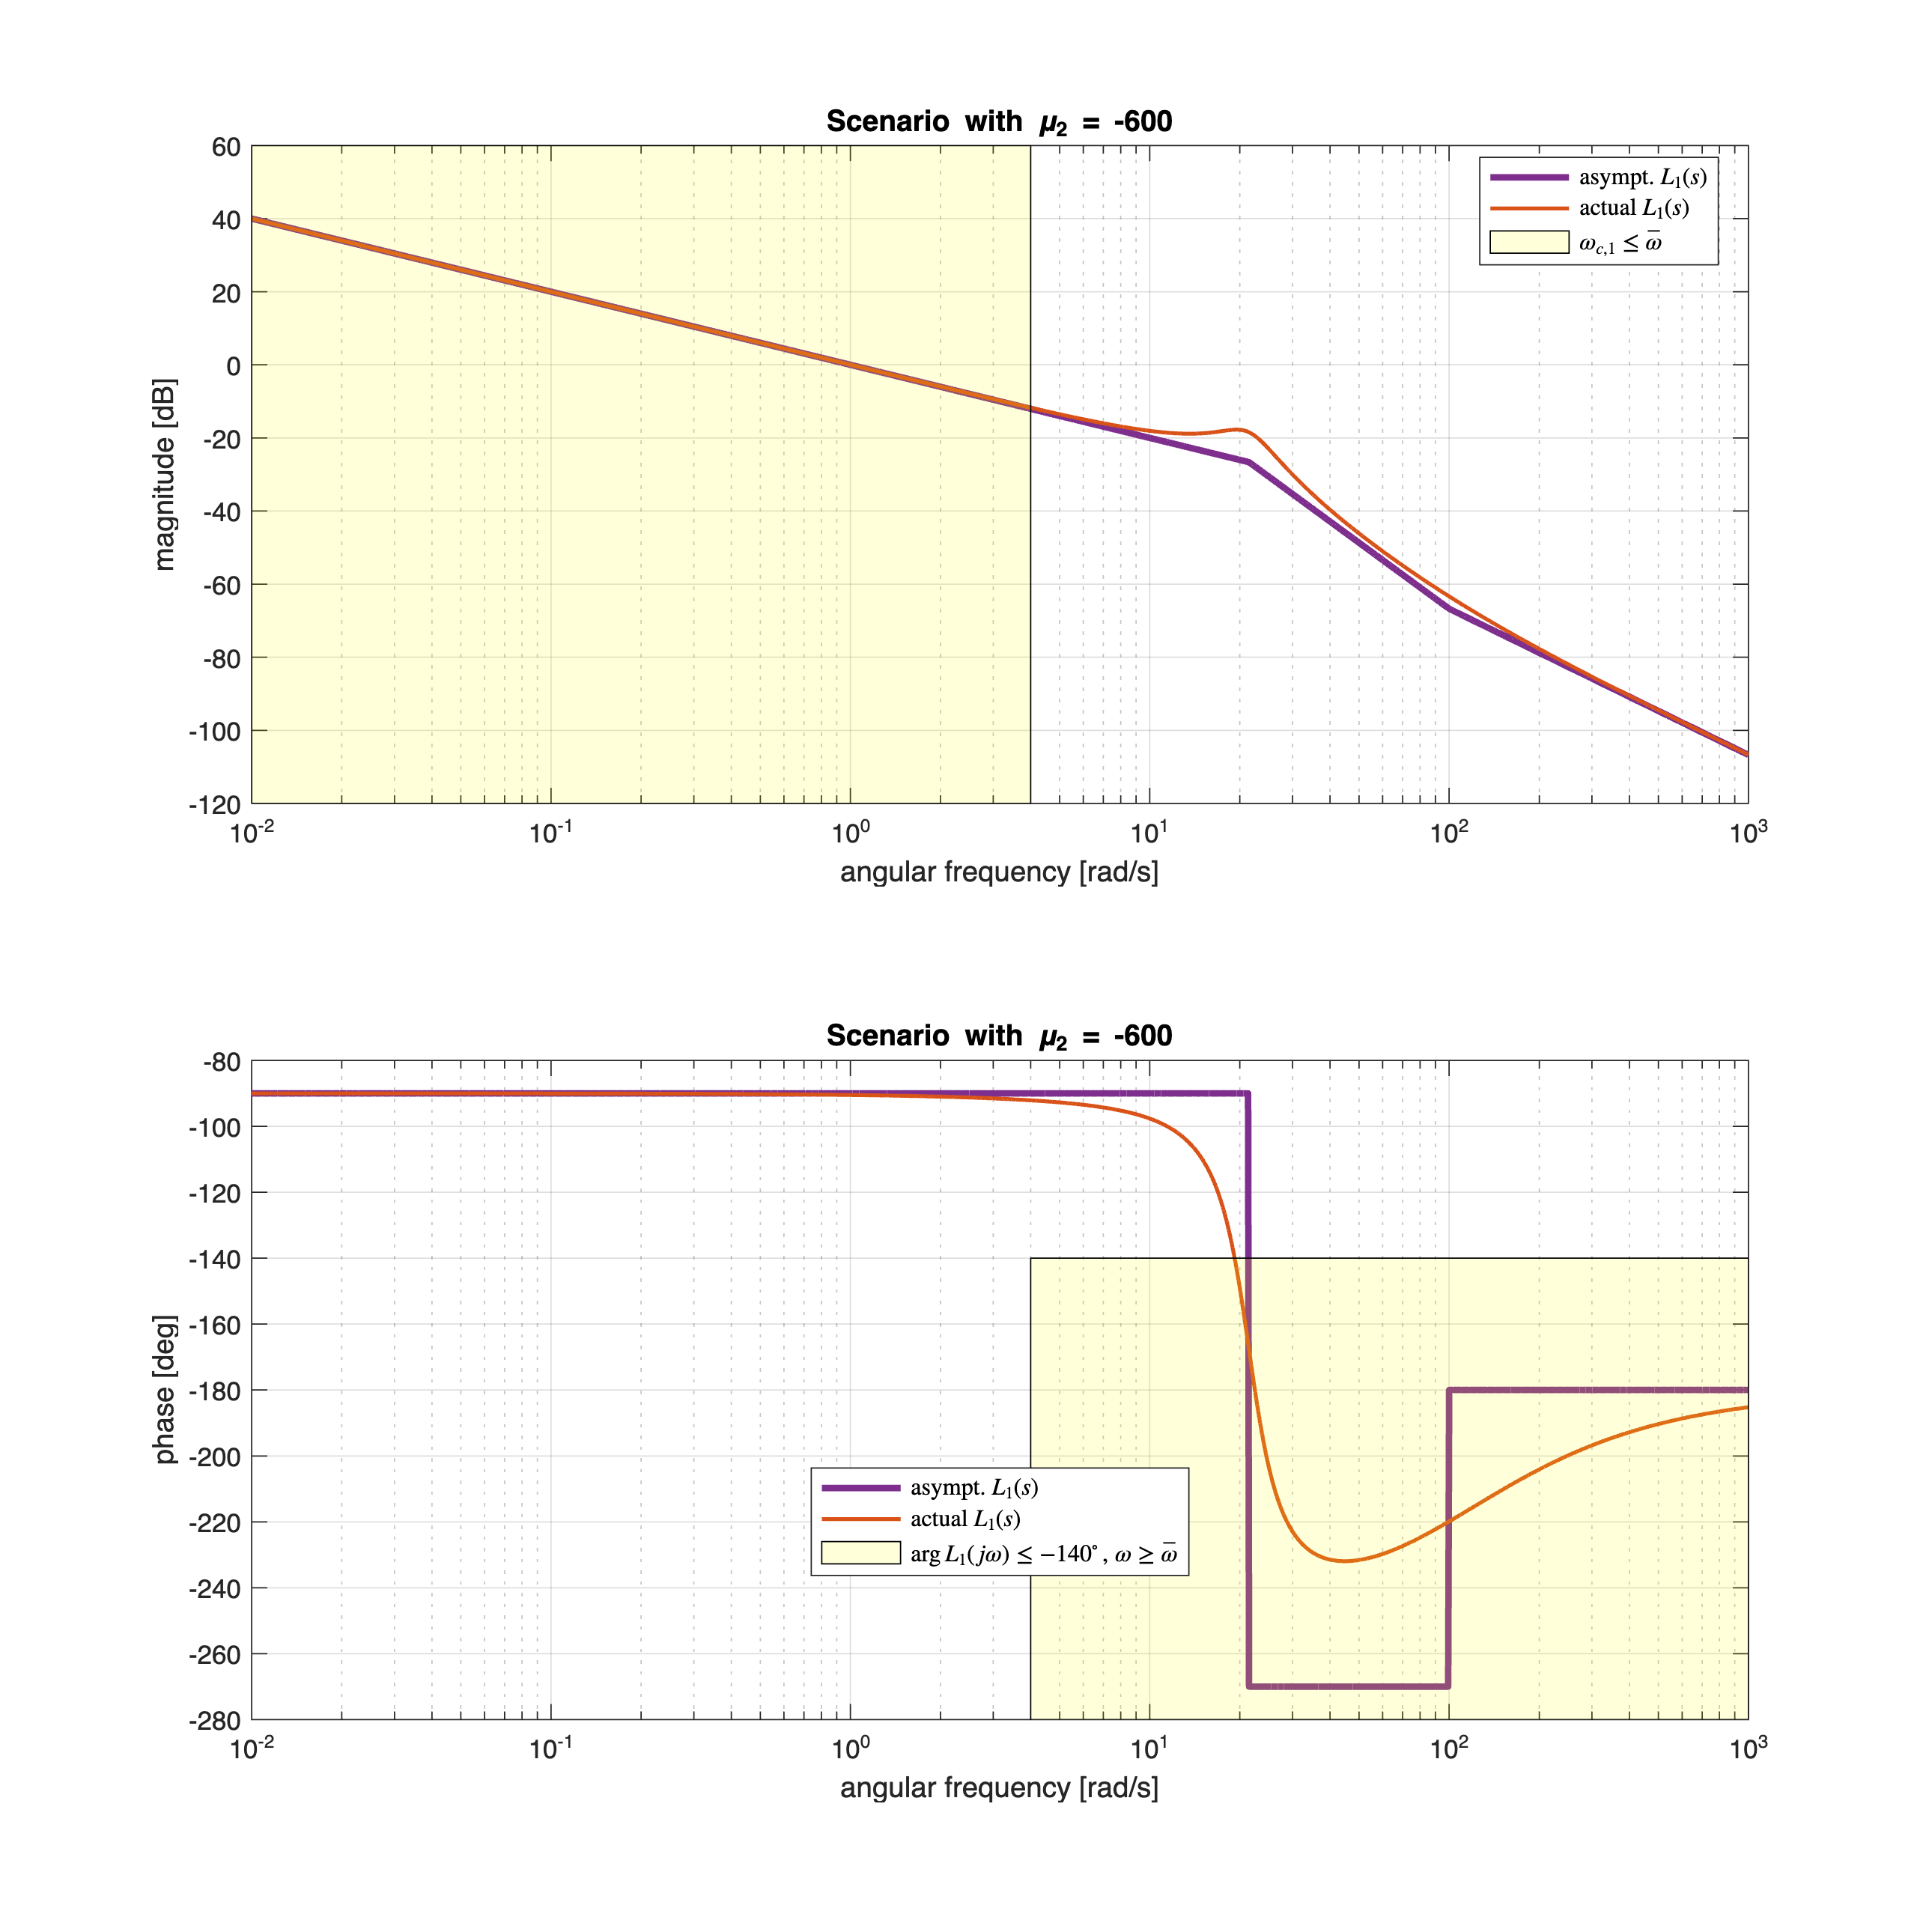

% --- 3rd case: mu2 = -600 ---
hf3 = figure('Units','centimeters', 'Position',[0.1,0.1, 26, 26]);

L1_s = C1s*F2s_3; % <-- the open-loot transfer function for the outer loop

omVALS = logspace(-2, 3, 1e5); % ang. freqs in [1/100; 1000]
[hax1, hax2] = drawBodediagrams(L1_s, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hf3);

rLimOmega = min(xlim(hax1)); % the minimum value of the ang. frequency in the drawing
Yl = ylim(hax1); % the minimum and the maximum values of the frequency response
                 % magnitude in the drawing

Vert1 = [barOmega Yl(1); barOmega Yl(2); rLimOmega Yl(1); rLimOmega Yl(2)];
Faces1 = [1  2  4  3];
patch(hax1, 'Faces',Faces1,'Vertices',Vert1,'FaceColor','yellow','FaceAlpha',.15);

rLimOmega = max(xlim(hax2)); % the maximum value of the ang. frequency in the drawing
PH_Yl = ylim(hax2); % the minimum and the maximum values of the frequency response
                 % phase in the drawing
Vert2 = [barOmega min(PH_Yl); barOmega min(Ph_Constraint, max(PH_Yl));...
         rLimOmega min(PH_Yl); rLimOmega min(Ph_Constraint, max(PH_Yl))];
Faces2 = [1  2  4  3];
patch(hax2, 'Faces',Faces2,'Vertices',Vert2,'FaceColor','yellow','FaceAlpha',.15);

title(hax1, ['Scenario with \mu_2 = ', num2str(mu2_TRIAL(3))]);
title(hax2, ['Scenario with \mu_2 = ', num2str(mu2_TRIAL(3))]);

legend(hax1,  'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
             ' $\omega_{c,1} \le \bar{\omega}$','Location', 'best', ...
             'Interpreter', 'latex');
legend(hax2,  'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
             '$\arg L_1(j \omega) \le -140^{\circ}\,,\; \omega \ge \bar{\omega}$',...
             'Location', 'best', 'Interpreter', 'latex');

**Remark**: The pale yellow regions correspond to the forbidden zones, respectively for the crossover angular frequency $\omega_{c\,1}$ and for the frequency response phase $\arg L_1(j \omega)$. 

- Note: to obtain a crossover frequency $\omega_{c\,1}$ fulfilling the requirement Q1.3, you should increase the gain constant $\mu_1$.

- For $ 4 \le \omega \le 10 \; \text{rad/s}$, the frequency response phase $\arg L_1(j \omega)$ is fulfilling the constraint. 

- Pay attention to the **resonance peak** in the frequency response **magnitude** diagram. 

- The **asymptotic** curve and the **actual** **magnitude** curve **overlap** for frequencies up to about $6$ rad/s, and then the actual curve is above the asymptotic curve due to the resonance peak. Only for angular frequencies above $200$ rad/s do the two curves overlap again.

- Note how the **phase margin quickly drops** when the angular frequency $\omega$ is increasing from $10$ to $20\; \text{rad/s}$.

-  If you would obtain $\omega_{c\,1} \ge 10$, the required phase margin can be obtained  by adding one zero to the controller transfer function.

- To keep the design as easy as possible, you should design an integral controller imposing $4 \le \omega_{c\,1} \le 6$ and tuning the gain $\mu_1$properly: due to the resonance peak in the magnitude response, you may fine tune $\mu_1$ using the `controlSystemDesigner` App.

**The Fourth Scenario: **$\mathbf{\mu_2 = -1200}$

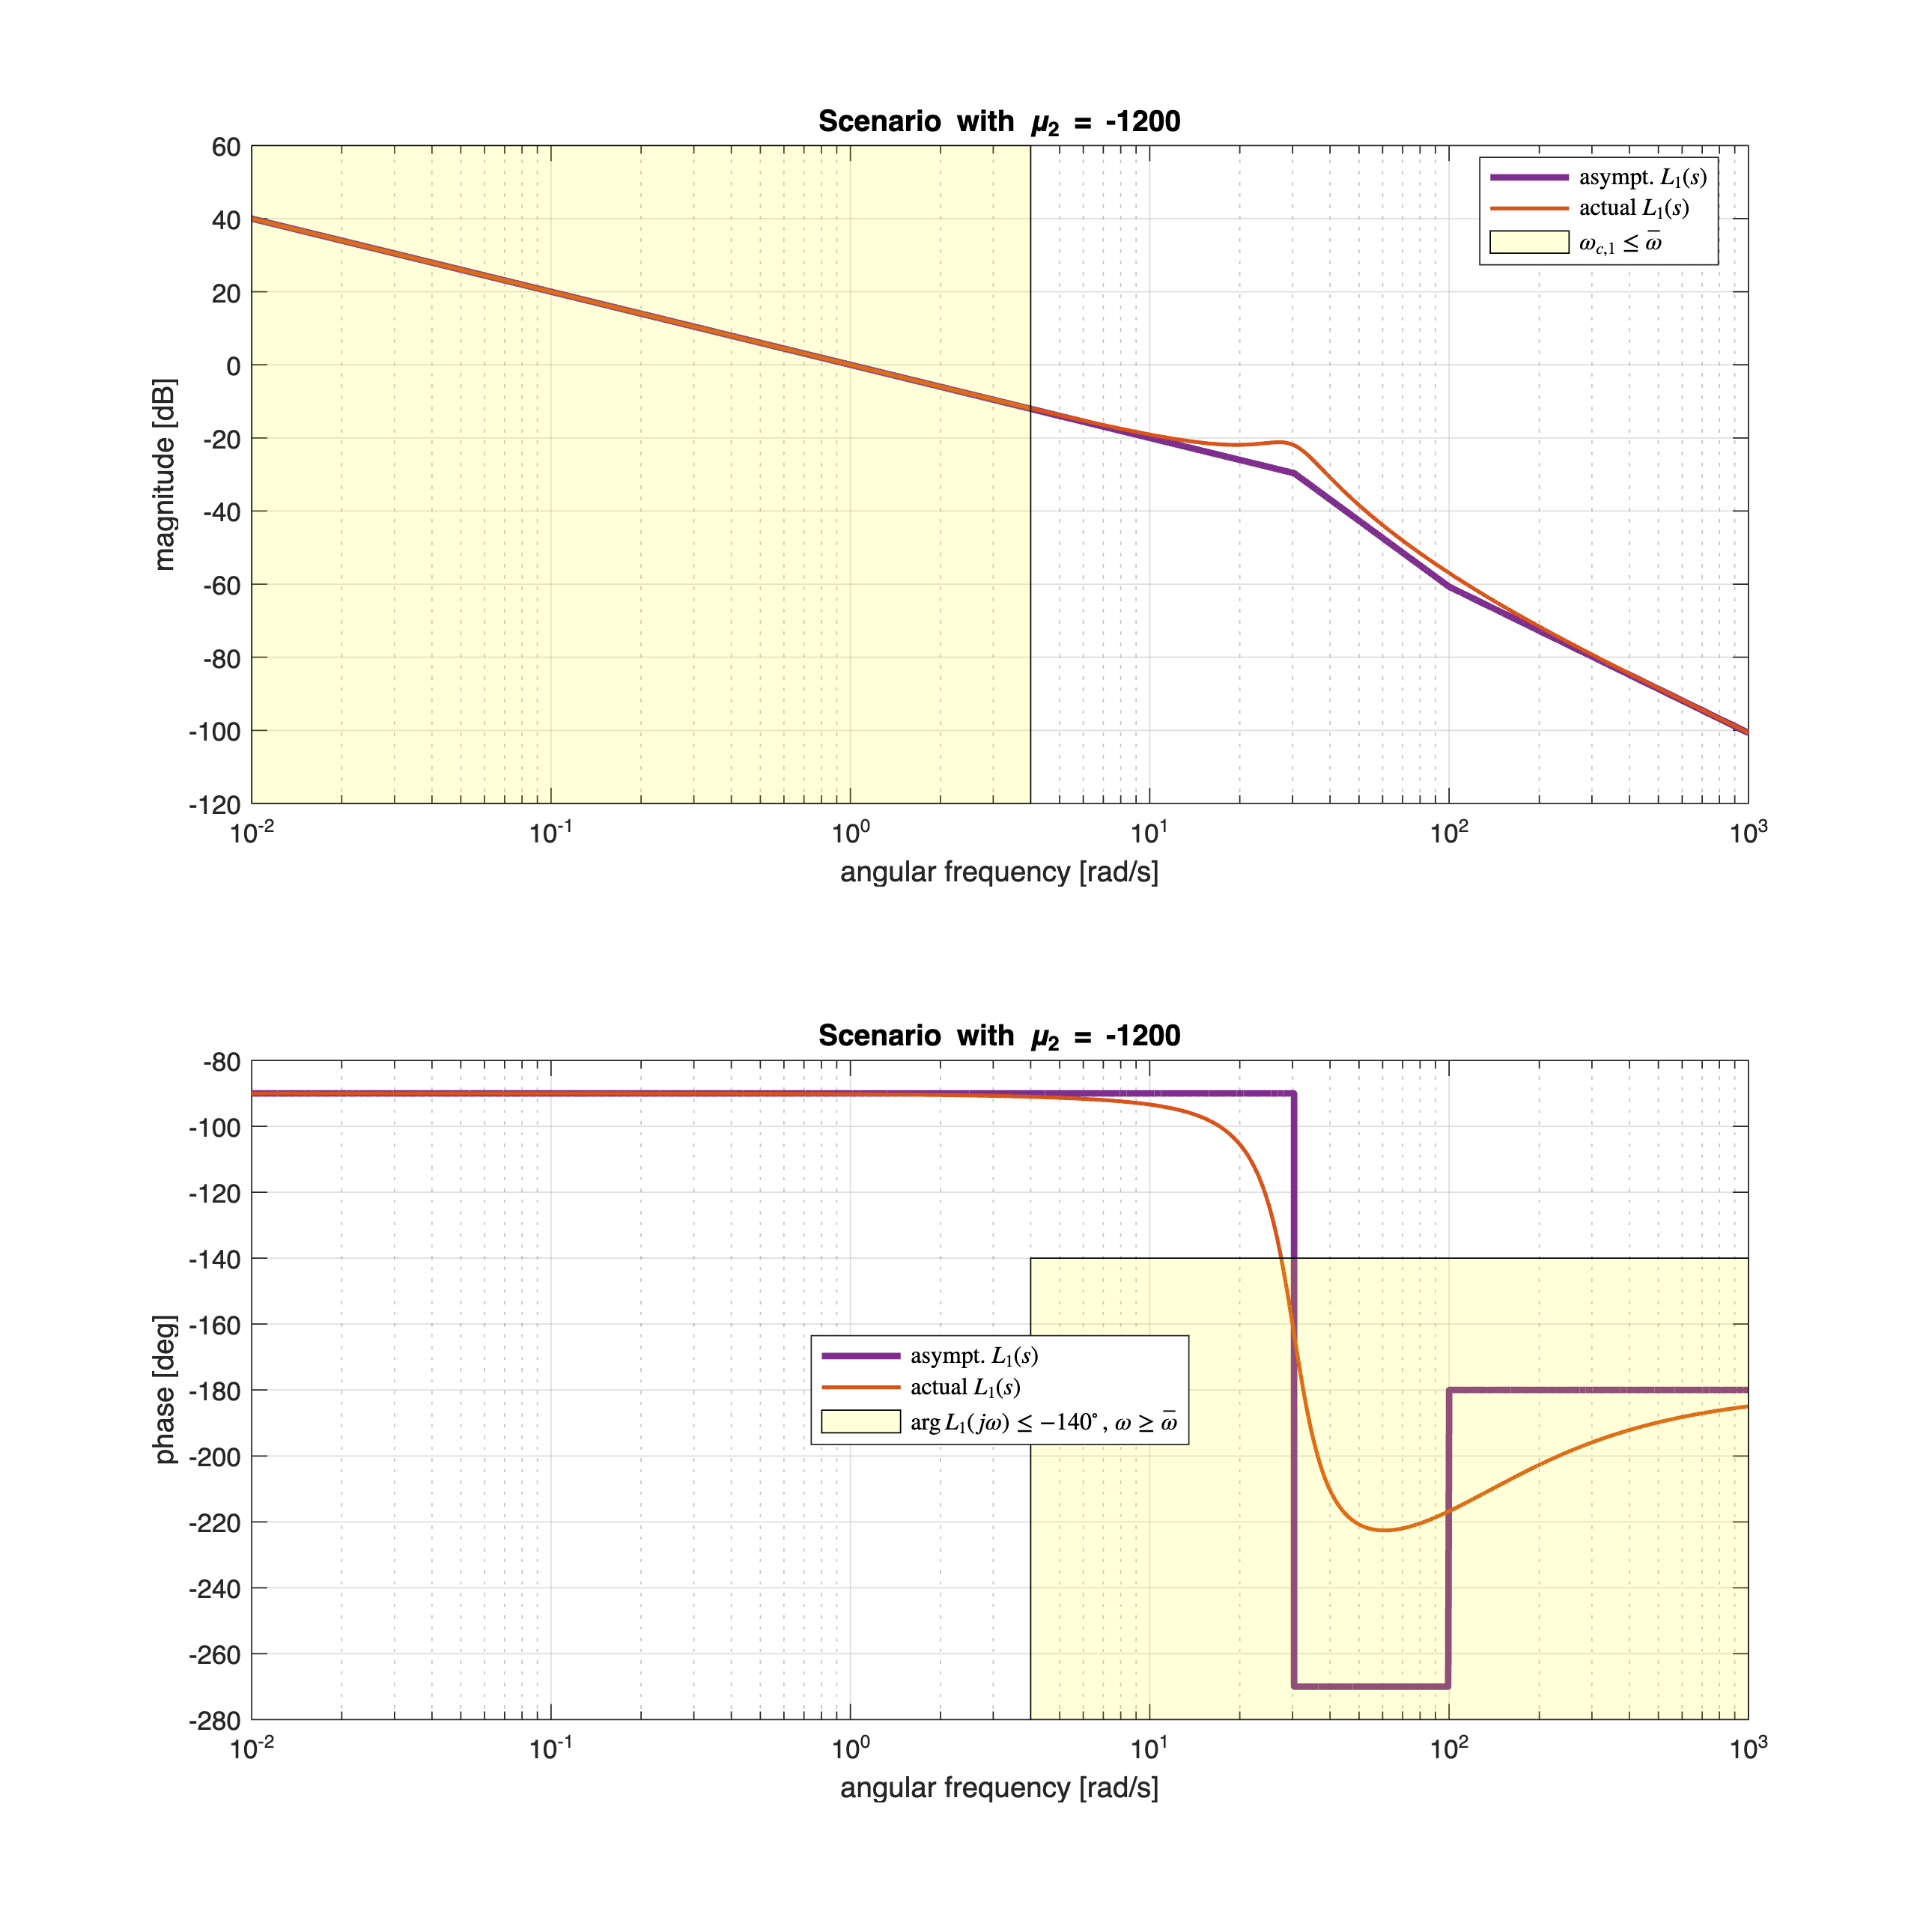

% --- 4th case: mu2 = -1200 ---
hf4 = figure('Units','centimeters', 'Position',[0.1,0.1, 26, 26]);

L1_s = C1s*F2s_4; % <-- the open-loot transfer function for the outer loop

omVALS = logspace(-2, 3, 1e5); % ang. freqs in [1/100; 1000]
[hax1, hax2] = drawBodediagrams(L1_s, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hf4);

rLimOmega = min(xlim(hax1)); % the minimum value of the ang. frequency in the drawing
Yl = ylim(hax1); % the minimum and the maximum values of the frequency response
                 % magnitude in the drawing

Vert1 = [barOmega Yl(1); barOmega Yl(2); rLimOmega Yl(1); rLimOmega Yl(2)];
Faces1 = [1  2  4  3];
patch(hax1, 'Faces',Faces1,'Vertices',Vert1,'FaceColor','yellow','FaceAlpha',.15);

rLimOmega = max(xlim(hax2)); % the maximum value of the ang. frequency in the drawing
PH_Yl = ylim(hax2); % the minimum and the maximum values of the frequency response
                 % phase in the drawing
Vert2 = [barOmega min(PH_Yl); barOmega min(Ph_Constraint, max(PH_Yl));...
         rLimOmega min(PH_Yl); rLimOmega min(Ph_Constraint, max(PH_Yl))];
Faces2 = [1  2  4  3];
patch(hax2, 'Faces',Faces2,'Vertices',Vert2,'FaceColor','yellow','FaceAlpha',.15);

title(hax1, ['Scenario with \mu_2 = ', num2str(mu2_TRIAL(4))]);
title(hax2, ['Scenario with \mu_2 = ', num2str(mu2_TRIAL(4))]);

legend(hax1,  'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
             ' $\omega_{c,1} \le \bar{\omega}$','Location', 'best', ...
             'Interpreter', 'latex');
legend(hax2,  'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
             '$\arg L_1(j \omega) \le -140^{\circ}\,,\; \omega \ge \bar{\omega}$',...
             'Location', 'best', 'Interpreter', 'latex');

**Remark**: The pale yellow regions correspond to the forbidden zones, respectively for the crossover angular frequency $\omega_{c\,1}$ and for the frequency response phase $\arg L_1(j \omega)$. 

- Note: to obtain a crossover frequency $\omega_{c\,1}$ fulfilling the requirement Q1.3, you should increase the gain constant $\mu_1$.

- For $ 4 \le \omega \le 20 \; \text{rad/s}$, the frequency response phase $\arg L_1(j \omega)$ is fulfilling the constraint. 

- Pay attention to the **resonance peak** in the frequency response **magnitude** diagram. 

- The **asymptotic** curve and the **actual** **magnitude** curve **overlap** for frequencies up to about $9$ rad/s, and then the actual curve is above the asymptotic curve due to the resonance peak. Only for angular frequencies above $200$ rad/s do the two curves overlap again.

- Note how the **phase margin quickly drops** when the angular frequency $\omega$ is increasing from $20$ to $30\; \text{rad/s}$.

-  If you would obtain $\omega_{c\,1} \ge 20$, the required phase margin can be obtained  by adding one zero to the controller transfer function.

- To keep the design as easy as possible, you should design an integral controller imposing $4 \le \omega_{c\,1} \le 9$ and tuning the gain $\mu_1$properly: due to the resonance peak in the magnitude response, you may fine tune $\mu_1$ using the `controlSystemDesigner` App.

#### The Choice of the Inner Controller Gain: Concluding Remarks

- The analysis using the Bode diagrams is more effective than exploiting the root locus; indeed, you have the cross-over frequency corresponding to each possible choice for the gain $\mu_2$ and the information on the phase of the frequency response $L_1(j \omega)$ for each gain value. 

- If $\mu_2 = -600$ or $\mu_2 = -1200$, the design allows to easily obtain the crossover frequency $\omega_{c\,1}$ higher than the required frequency $\bar \omega = 4$; moreover, when $\omega_{c\,1} \approx \bar{\omega}$ the frequency response phase is, in both the cases, far from the requirement constraint $\arg L_1(j \omega) \ge -140^{\circ}$ [the worst case, supposing to apply a pure integral action for the controller $C_1(s)$] . In both the scenarios, if we would impose $\omega_{c\,1} = \bar \omega$ the outer loop controller $C_1(s)$ could be a simple integrator: $C_1(s) = \frac{\mu_1}{s}\,,\; \mu_1 >0$

- if $\mu_2 = -60$, the design allows to easily obtain the crossover frequency $\omega_{c\,1}$ equal or very close to the required frequency $\bar \omega = 4$;. Moreover, when $\omega_{c\,1} \approx \bar{\omega}$ the frequency response phase could be close to the worst case constraint $\arg L_1(j \omega) \ge  -140^{\circ}$ . The design of the controller $C_1(s)$ is probably not as simple as in the previous scenarios, and a zero in the controller to fulfil the phase margin requirement should be needed, if you would obtain $\omega_{c\,1} \ge \bar \omega$: $C_1(s) = \frac{\mu_1 (1+Ts)}{s}\,,\quad \mu_1 >0\,,\; T>0$

- if $\mu_2=-6$, when $\omega \approx \bar{\omega}$ the frequency response phase is lower than the worst case constraint $\arg L_1(j \omega) \ge  -140^{\circ}$ . In this scenario, the controller $C_1(s)$ could have a more complex structure, involving up to two zeros and poles: $C_1(s) = \frac{\mu_1 (1+T_1s) (1+T_2 s)}{s (1+\tau_1 s)}\,,\quad \mu_1 >0\,,\; T_1>0\,,\;T_2>0\,,\;\tau_1>0$

Summarising, choosing $\mu_2 = -600$ or $\mu_2 = -1200$ allows for a straightforward design of the outer loop controller $C_1(s)$, whereas in the other scenarios the design becomes more tricky due to the higher number of parameters to be fixed (controller gain and the time constants of zeros and a pole).

**Note**: Only the scenario with  $\mu_2=-600$ will be considered in the remaining part of this document.

### A  Few Proposals for Different Solutions

- Solve the problem for other gain $\mu_2$ values (for example $\mu_2=-6\,,\; -60\,,\;-1200$ or choose a different value). 

- What if the inner loop controller $C_2(s)$ is $C_2(s) = \mu_2 \frac{(1+4s)}{\left(1+\frac{s}{150}\right)}$ ? What happens to the Root Locus? Does this choice help simplify the design phase of the outer controller $C_1(s)$ or not?

### The Design of the Outer Loop when $\mathbf{\mu_2 = -600}$, using the Bode Diagrams

From now on, let's consider only the scenario with $\mu_2 = -600$. The correponding closed loop function $F_2(s)$ is given by:

mu2 = -600;    % the gain of the inner loop controller
C2s = tf(mu2); % the inner loop stabilising controller: a pure proportional controller
L2s = C2s * Gs;% the open-loop transfer function of the inner loop

F2s = feedback(L2s, 1, -1); % the closed loop transfer function of the inner loop
                            % actually, it's the plant transfer function 
                            % in the outer control loop 

% --- the outer controller C1s: an integral control action --- 
mu1 = 1;     % <-- preliminare gain constant
C1s = mu1/s; % the controller (as pointed out in the tex above, we could 
             % design a very simple controller C1s, able to fulfil all the
             % requirements

L1s = C1s * F2s; % <-- the open-loop transfer function



#### The Preliminar Bode Diagrams

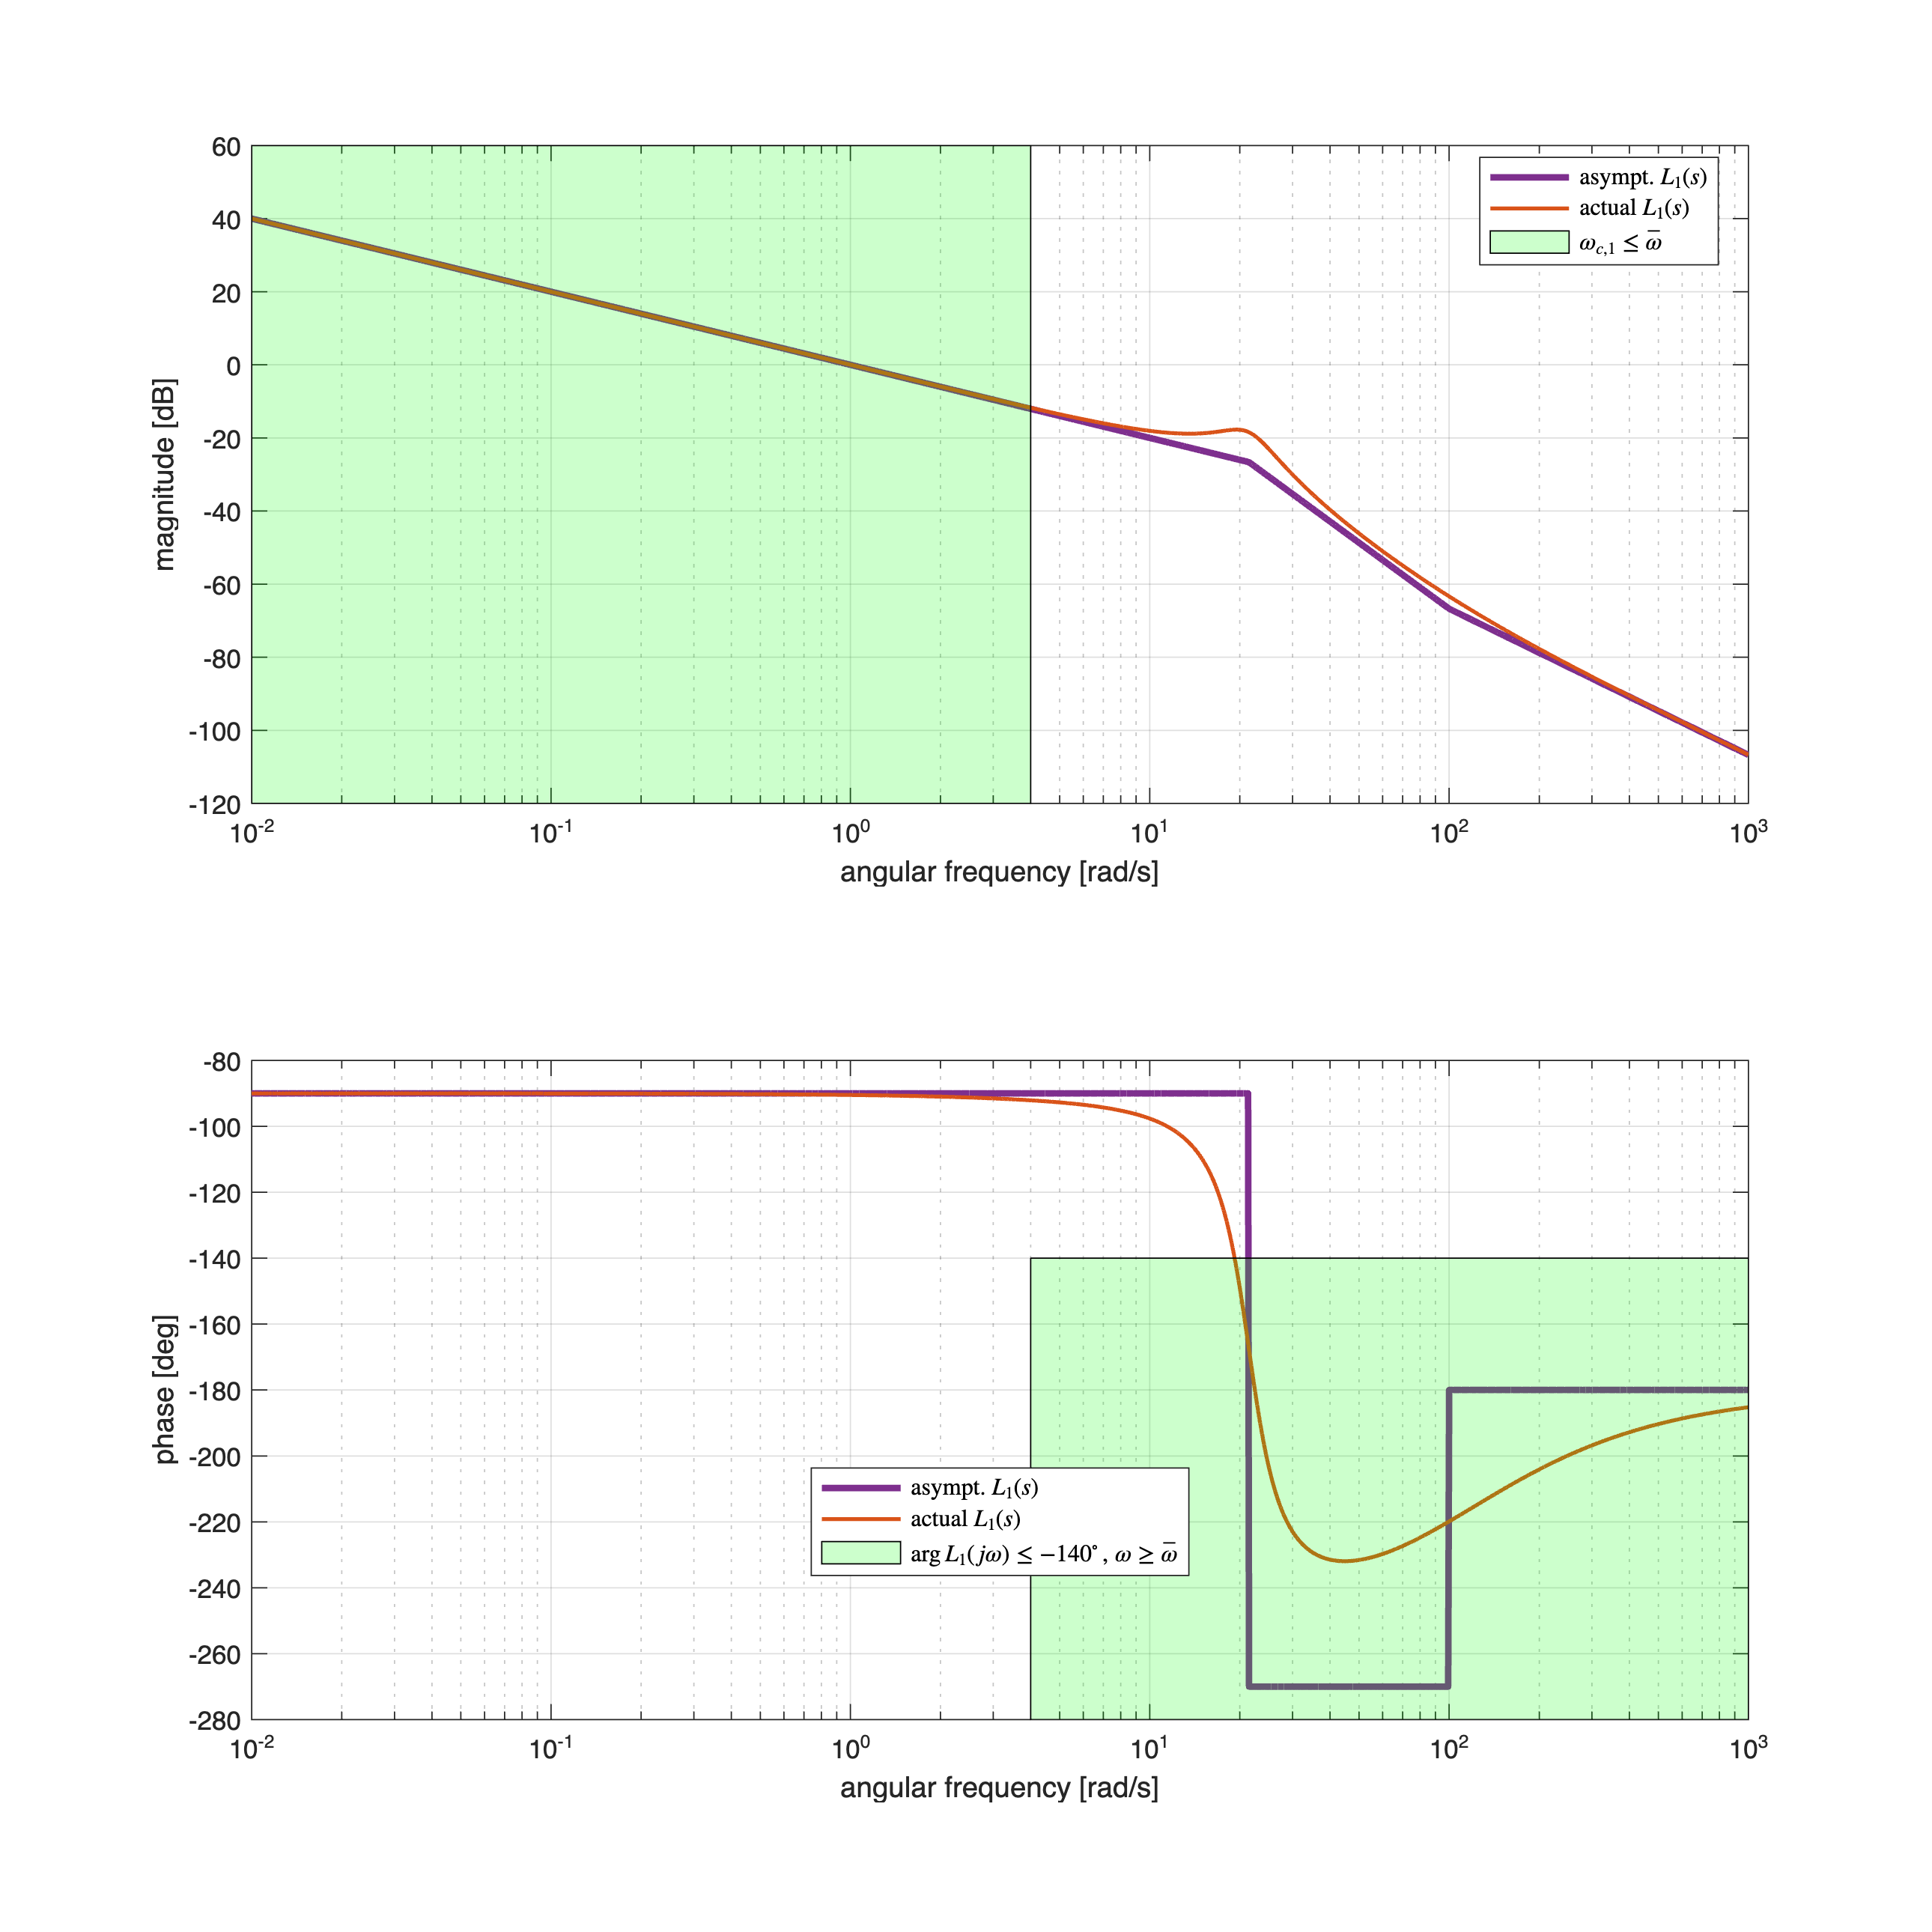

hfP = figure('Units','centimeters', 'Position',[0.1,0.1, 26, 26]);

omVALS = logspace(-2, 3, 1e5); % ang. freqs in [1/100; 1000]
[hax1, hax2] = drawBodediagrams(L1s, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hfP);

rLimOmega = min(xlim(hax1)); % the minimum value of the ang. frequency in the drawing
Yl = ylim(hax1); % the minimum and the maximum values of the frequency response
                 % magnitude in the drawing

Vert1 = [barOmega Yl(1); barOmega Yl(2); rLimOmega Yl(1); rLimOmega Yl(2)];
Faces1 = [1  2  4  3];
patch(hax1, 'Faces',Faces1,'Vertices',Vert1,'FaceColor','green','FaceAlpha',.20);

rLimOmega = max(xlim(hax2)); % the maximum value of the ang. frequency in the drawing
PH_Yl = ylim(hax2); % the minimum and the maximum values of the frequency response
                 % phase in the drawing
Vert2 = [barOmega min(PH_Yl); barOmega min(Ph_Constraint, max(PH_Yl));...
         rLimOmega min(PH_Yl); rLimOmega min(Ph_Constraint, max(PH_Yl))];
Faces2 = [1  2  4  3];
patch(hax2, 'Faces',Faces2,'Vertices',Vert2,'FaceColor','green','FaceAlpha',.20);

legend(hax1,  'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
             ' $\omega_{c,1} \le \bar{\omega}$','Location', 'best', ...
             'Interpreter', 'latex');
legend(hax2,  'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
             '$\arg L_1(j \omega) \le -140^{\circ}\,,\; \omega \ge \bar{\omega}$',...
             'Location', 'best', 'Interpreter', 'latex');

#### Design of the Outer Controller using the Bode Diagrams

According to the previously performed analysis, let's select $\hat \omega = 6\;\text{rad/s}$ as candidate crossover frequency: the requirement Q1.2 on the phase margin is already fulfilled. We have only to properly tune the gain constant $\mu_1$ of the controller. The actual gain is $\mu_1 = 1$ and the crossover frequency is $\tilde \omega_{c\,1} = 1\;\text{rad/s}$.You can note that the asymptotic and the effective magnitude diagrams are very close each other also when $\omega \approx 6 \;\text{rad/s}$, so to impose $\hat \omega = 6\;\text{rad/s}$ as crossover frequency, you have simply to set the controller gain:


$$\mu_1 = 6 \quad \Longrightarrow \quad C_1(s) = \frac{6}{s}$$


Thus:

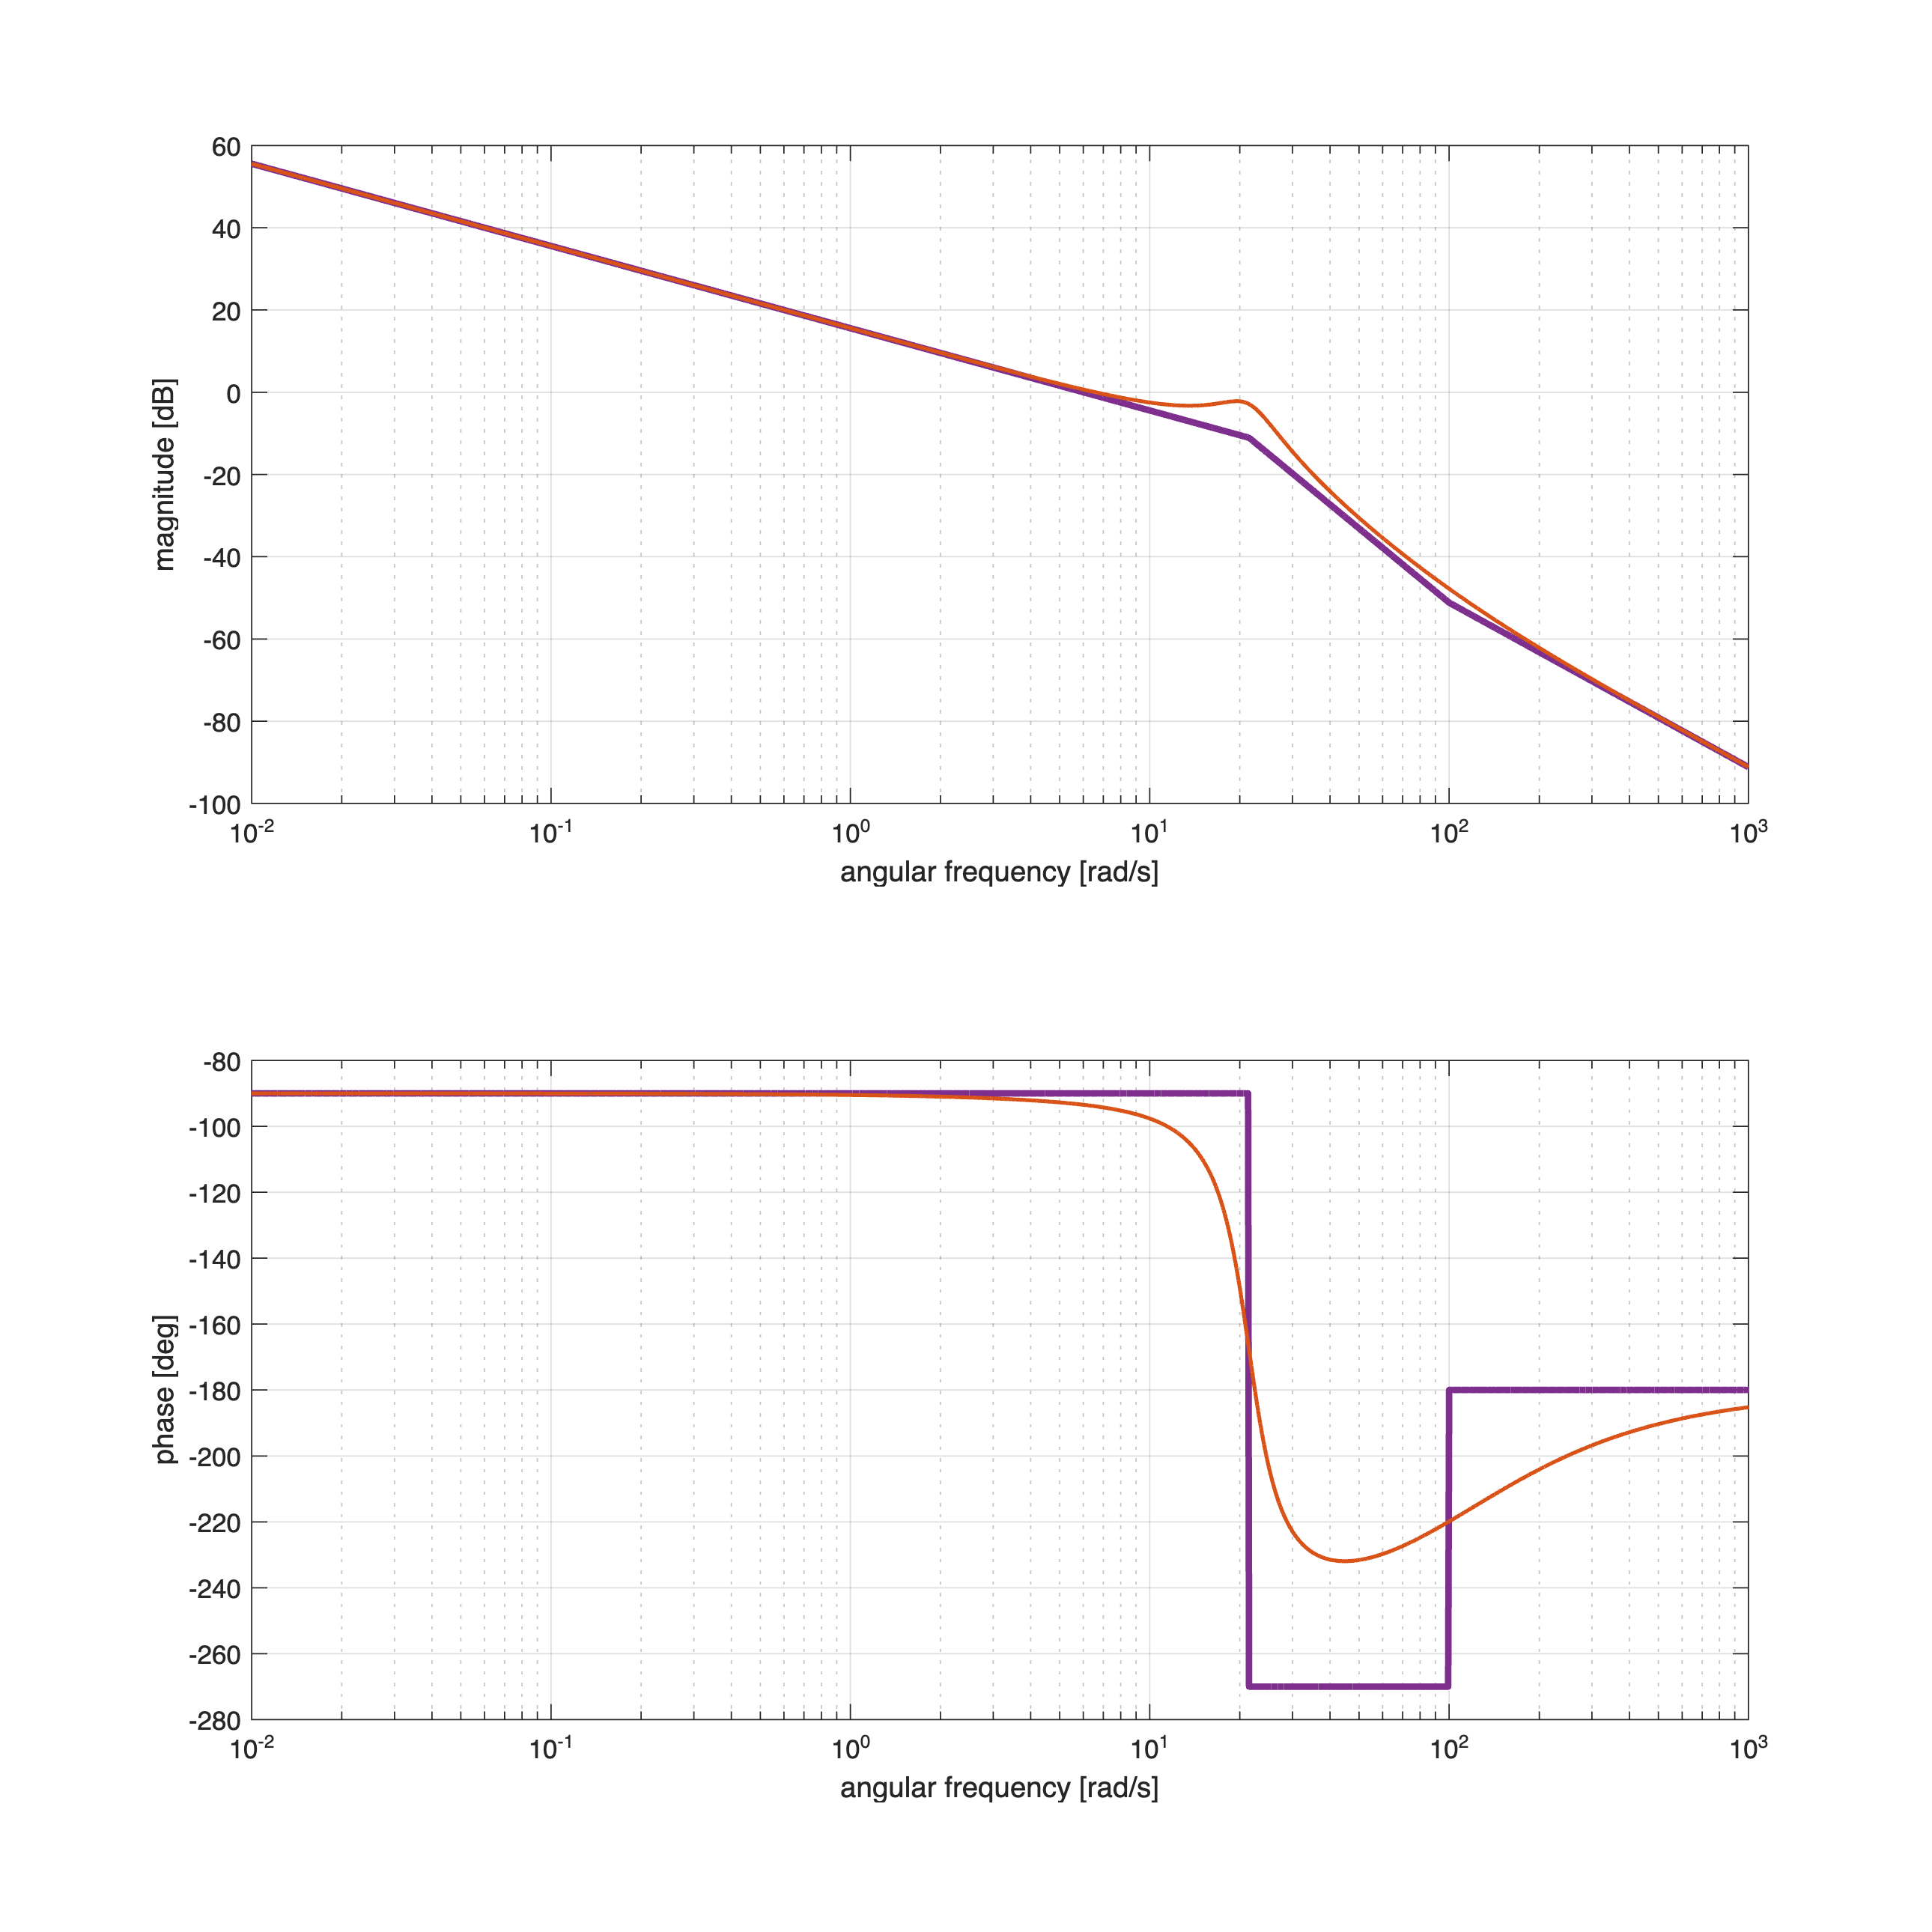

mu1_designBode = 6; % the new controller gain
C1s_designBode = mu1_designBode/s; % the controller

L1s_designBode = C1s_designBode * F2s; % let's update the open loop transfer function

hfFinal = figure('Units','centimeters', 'Position',[0.1,0.1, 26, 26]);

omVALS = logspace(-2, 3, 1e5); % ang. freqs in [1/100; 1000]
[hax1, hax2] = drawBodediagrams(L1s_designBode, omVALS, Bcolors(3, :), 2.5, '-', ...
                       Bcolors(6, :), 1.5, '-', hfFinal);

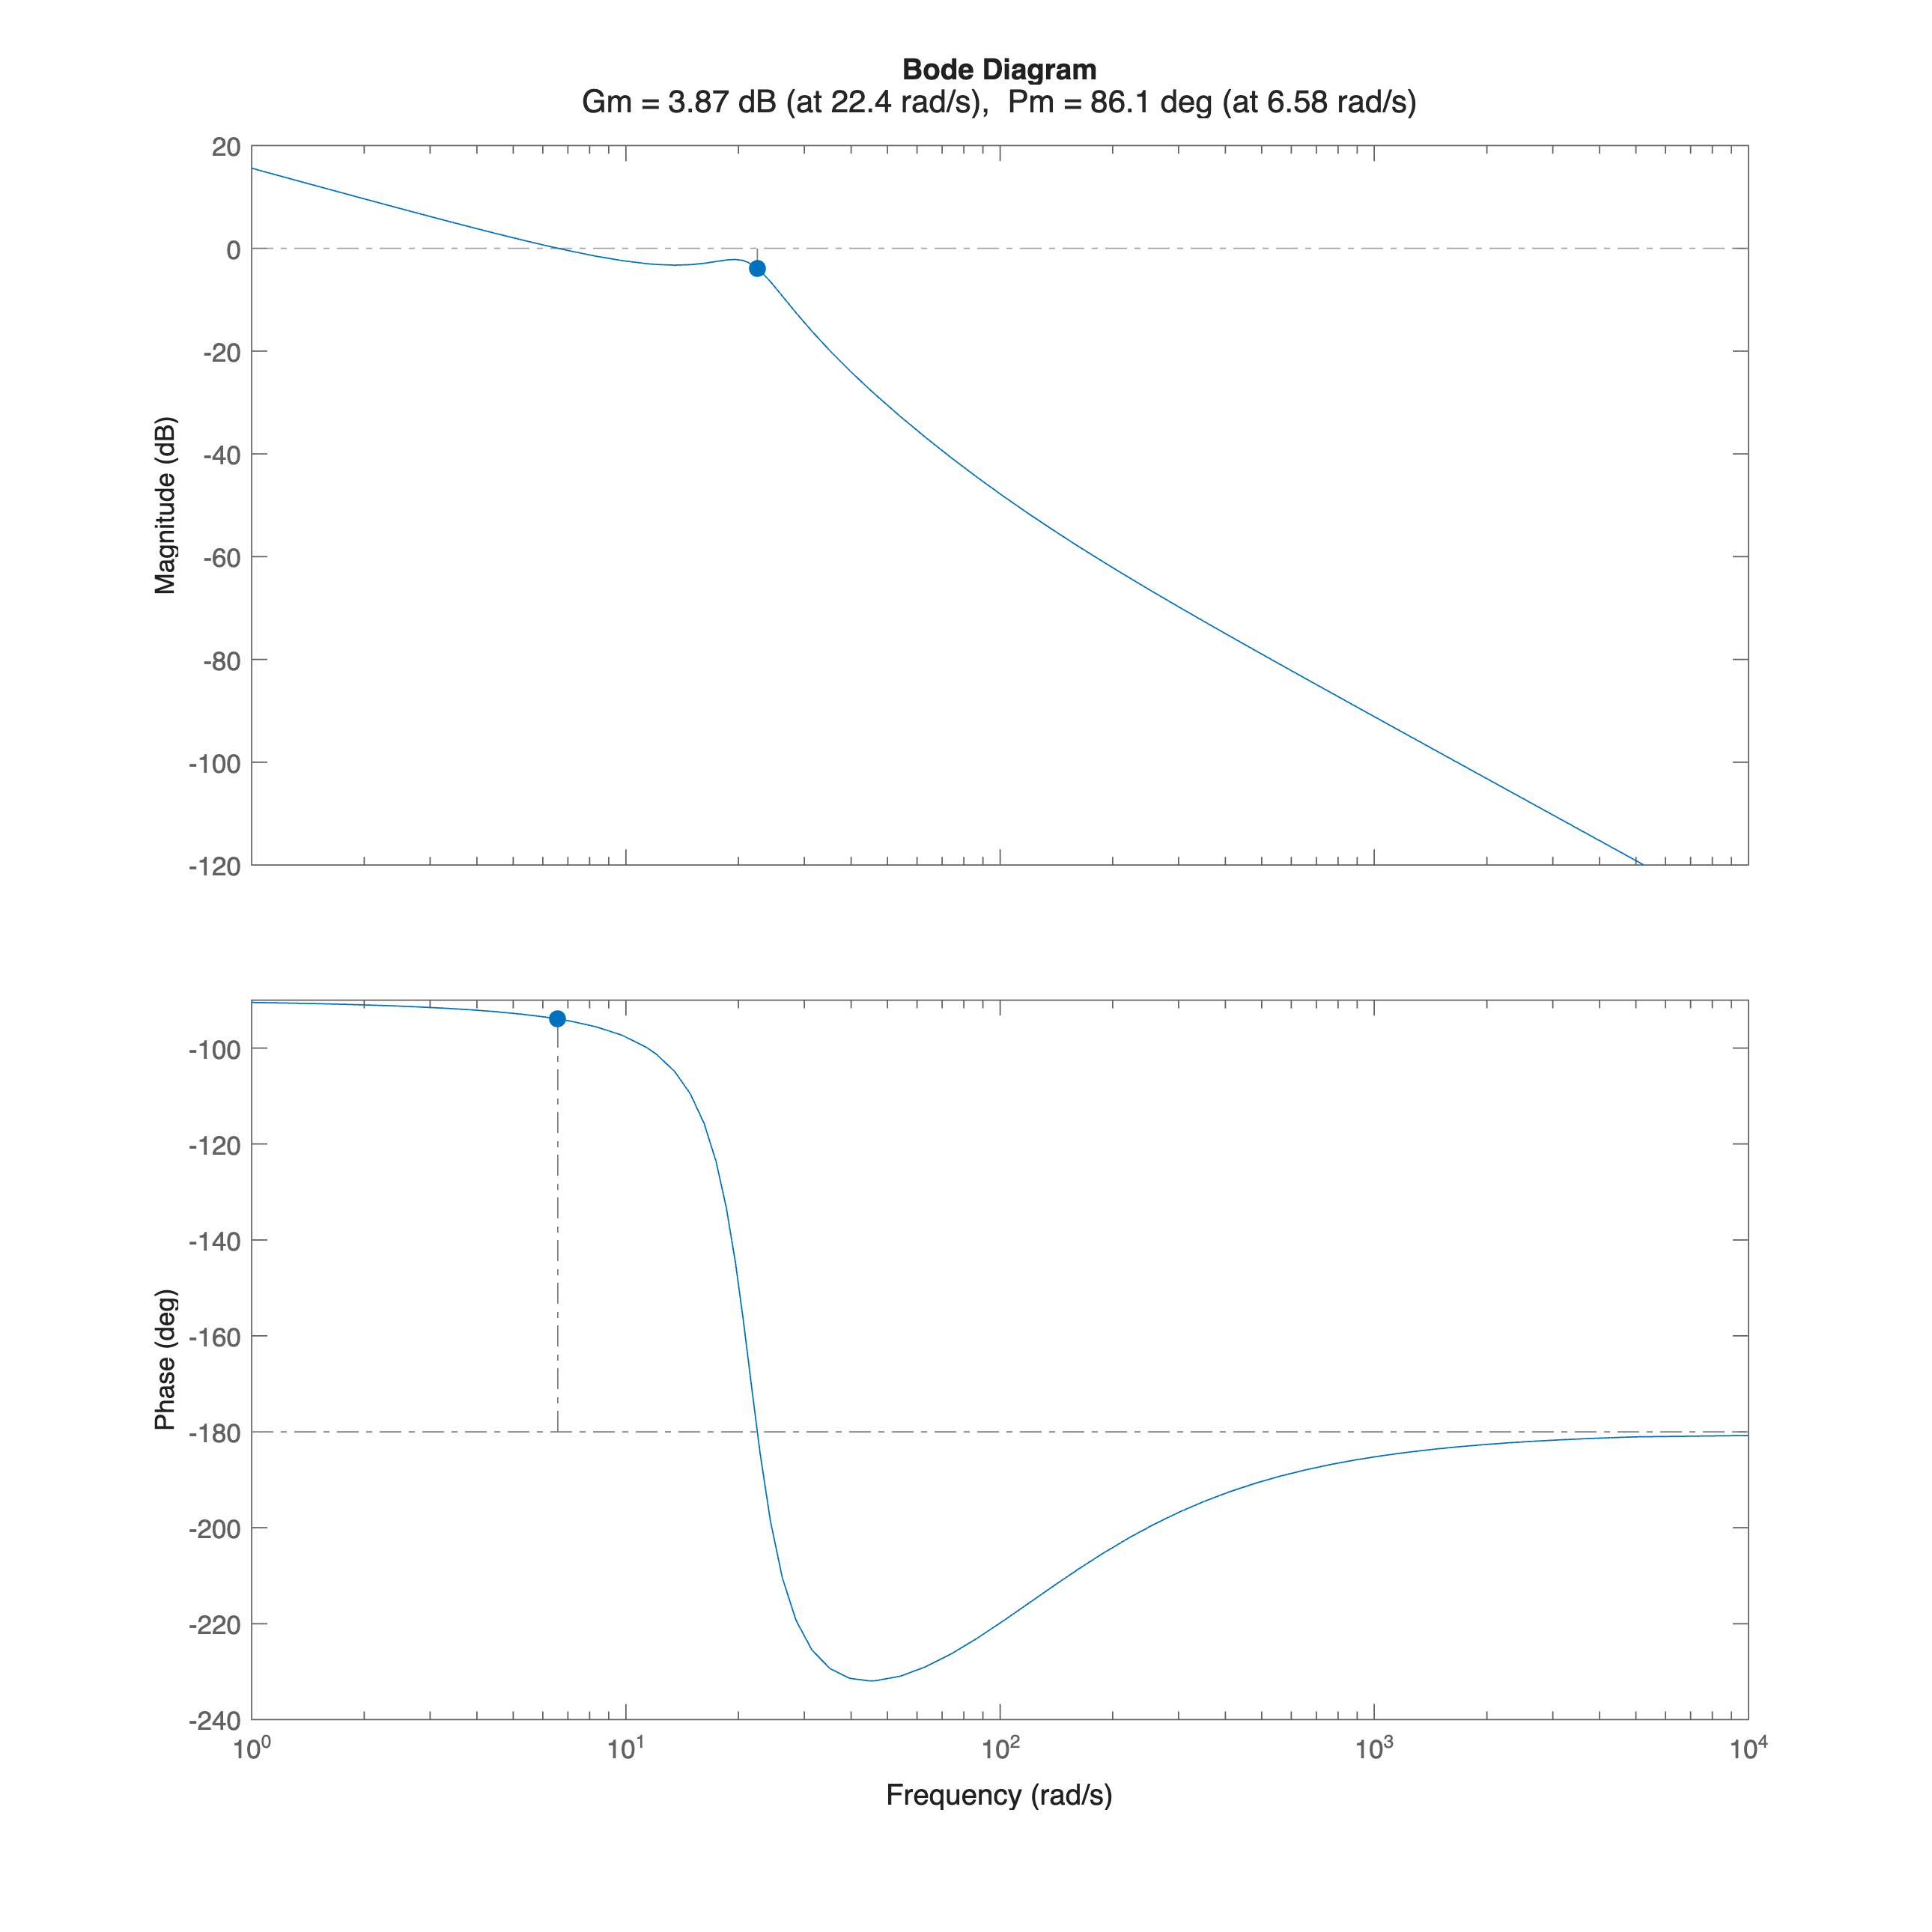


figure('Units','centimeters', 'Position',[0.1,0.1, 26, 26]);
margin(L1s_designBode);

The proposed solution fulfils all the requirements. You could fine tune the gain $\mu_1$ to obtain $\omega_{c\,1} = 6 \;\text{rad/s}$:

crossOverCandidate = 6;
% --- the outer controller C1s: an integral control action --- 
% mu1 = 1;     % <-- preliminare gain constant
% C1s = mu1/s; % the controller (as pointed out in the tex above, we could 
%              % design a very simple controller C1s, able to fulfil all the
%              % requirements
% 
% L1s = C1s * F2s; % <-- the open-loop transfer function

mu1_fineTuned = 1/abs(freqresp(L1s, crossOverCandidate))

mu1_fineTuned = 5.5595

Finally, the designed outer controller $C_1(s)$ is


$$C_1(s) = \frac{5.56}{s}$$


### The Fine Tuning of the Outer Loop when $\mathbf{\mu_2 = -600}$, using the ControlSystemDesigner App

The proposed solution provides the controllers:


$$C_2(s) = -600 \,,\qquad C_1(s) = \frac{5.56}{s}$$


Let's verify the performance using the `controlSystemDesigner` App

controlSystemDesigner;

Select the dual-loop control scheme configuration in the Control System Designer.

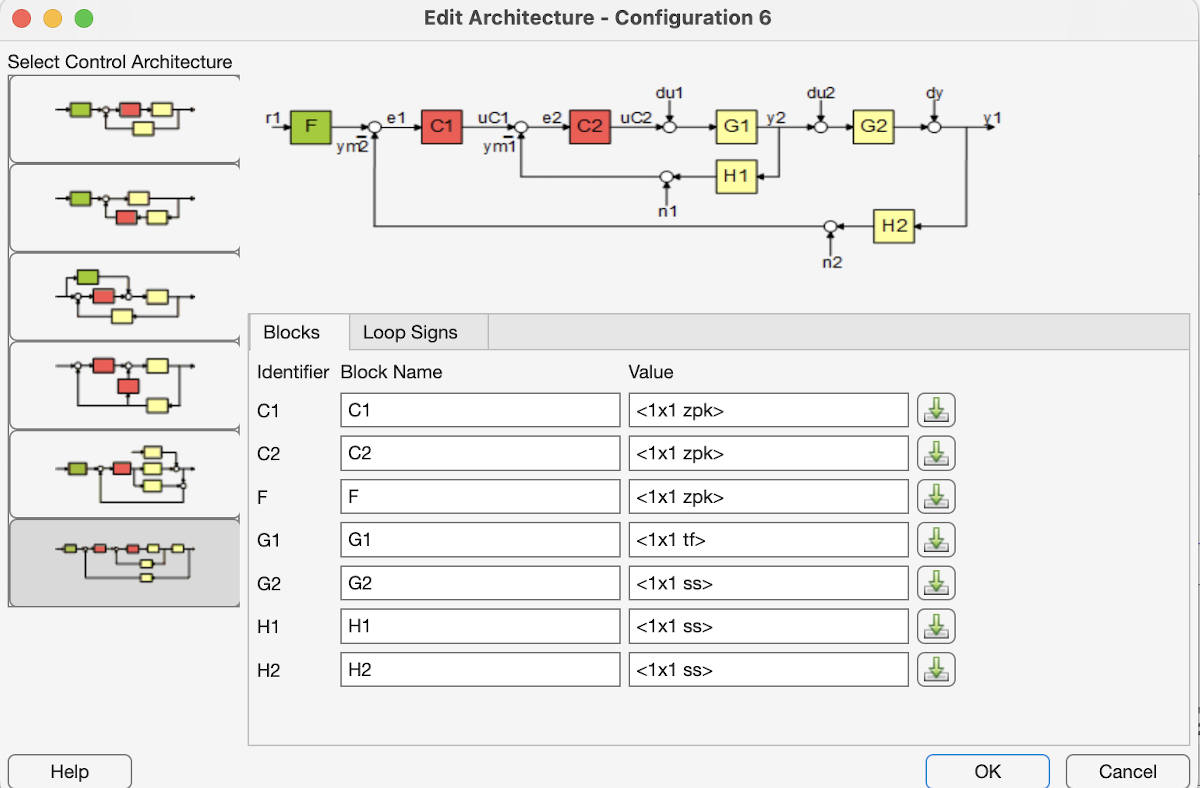

Import the `tf-object Gs` as the transfer function $G_1(s)$ in the block diagram. Let the transfer function $G_2(s)$ as is, i.e. a simple algebraic block $G_2(s) = 1$. 

#### Analysis and Tuning of the Inner Loop

Cut off the outer-loop controller, by setting $C_1(s) = 0$, when you are analysing the stability of the inner loop using the Root Locus Editor. Otherwise, you will analyse the effect of having both loops acting toghether (i.e., the outer loop interacts with the inner loop) and a useless root locus.

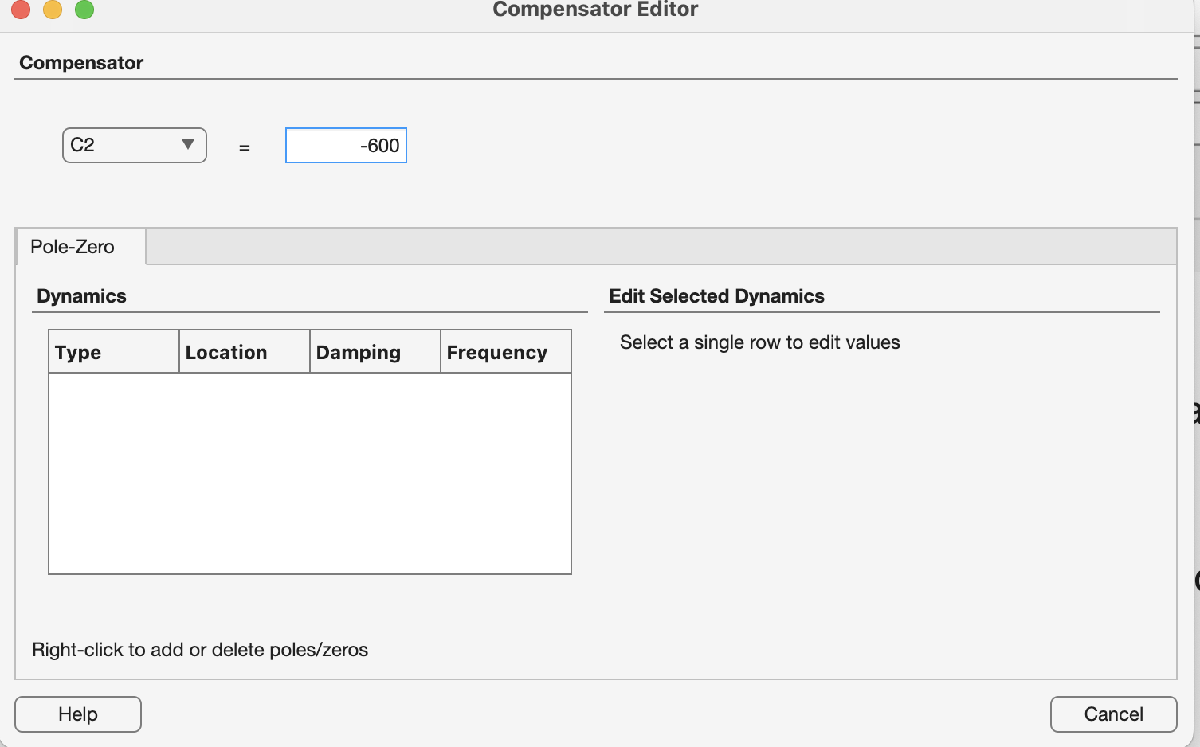

Letting $C_2(s) = -600$ we stabilise the inner loop, as confirmed by inspection of the root locus (of the inner loop):

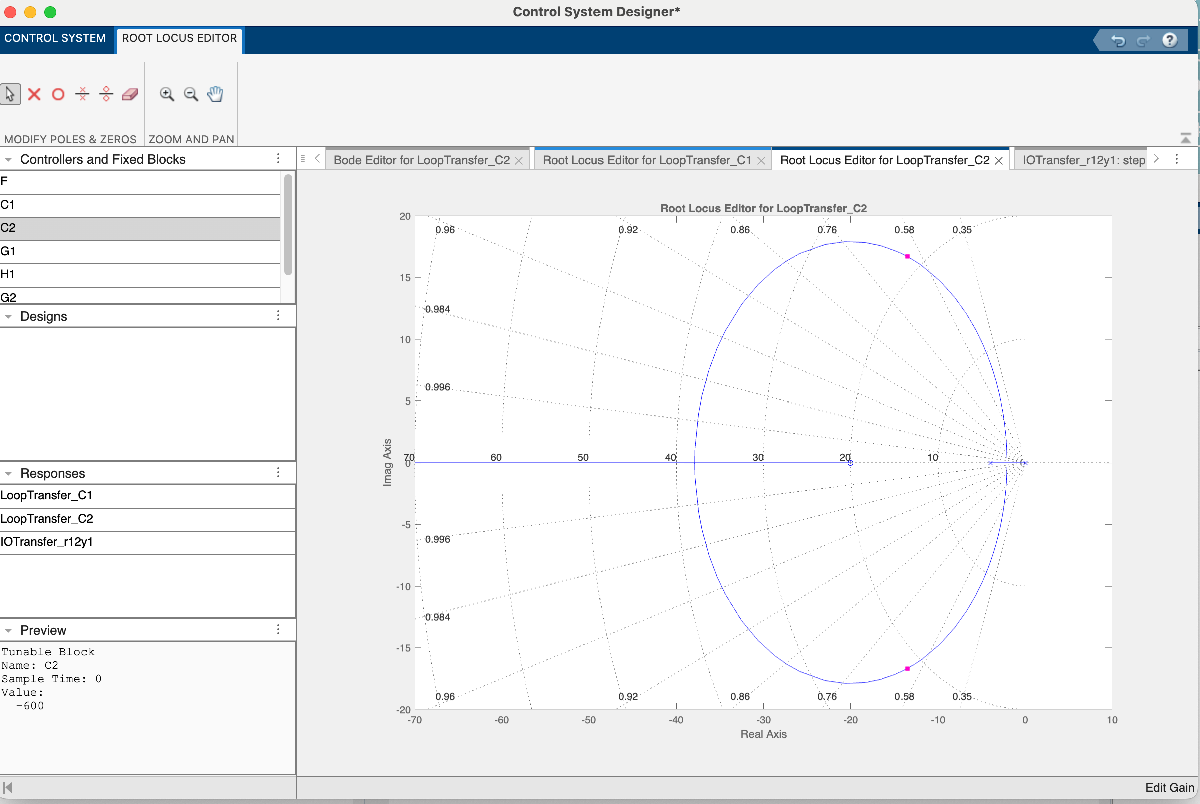

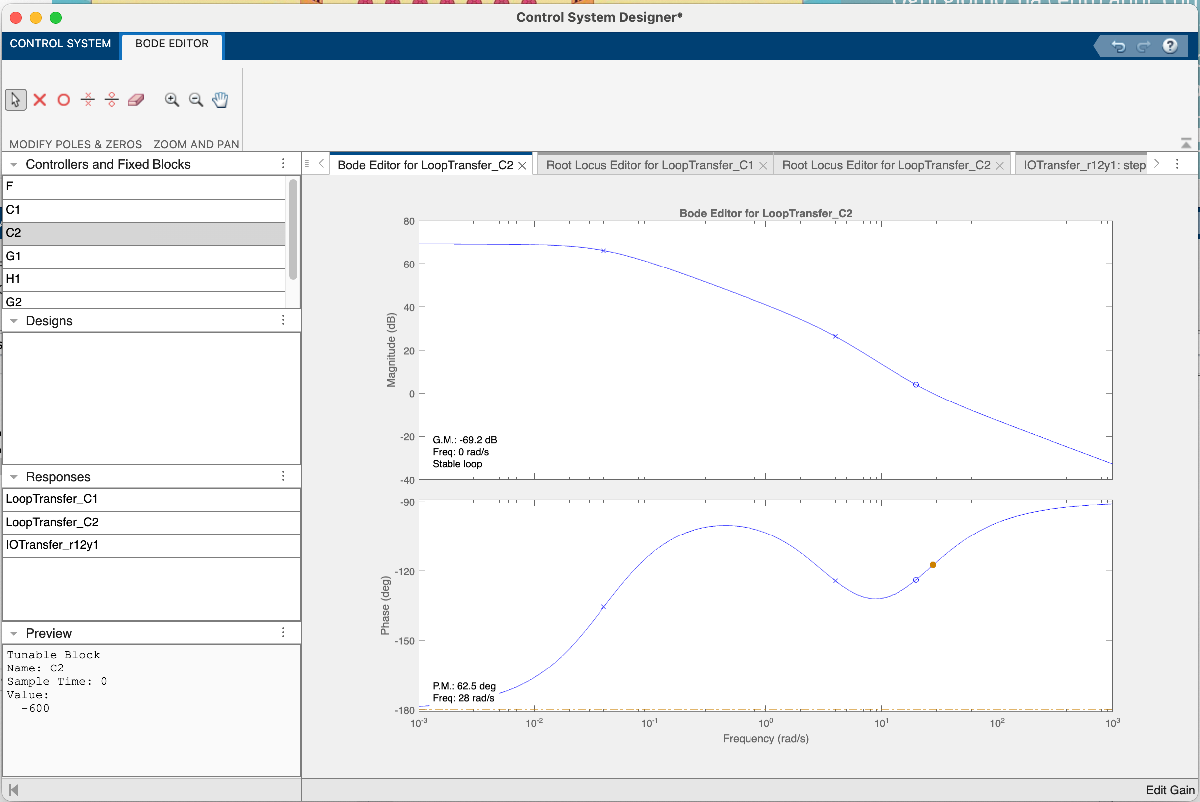

ControlSystemDesigner session: `ControlSystemDesignerSession_stabilisingC2.mat`

#### The Tuning of the Outer Loop

According to Req. Q1.3:     $C_1(s) = \frac{ \mu_{C}}{s}$

Increasing $\mu_C$ we are able to impose a cross-over frequency satisfying both the req.s Q1.1 and Q1.2: with $\mu_C=5.56$ we obtain


$$C_1(s) = \frac{5.56}{s}$$


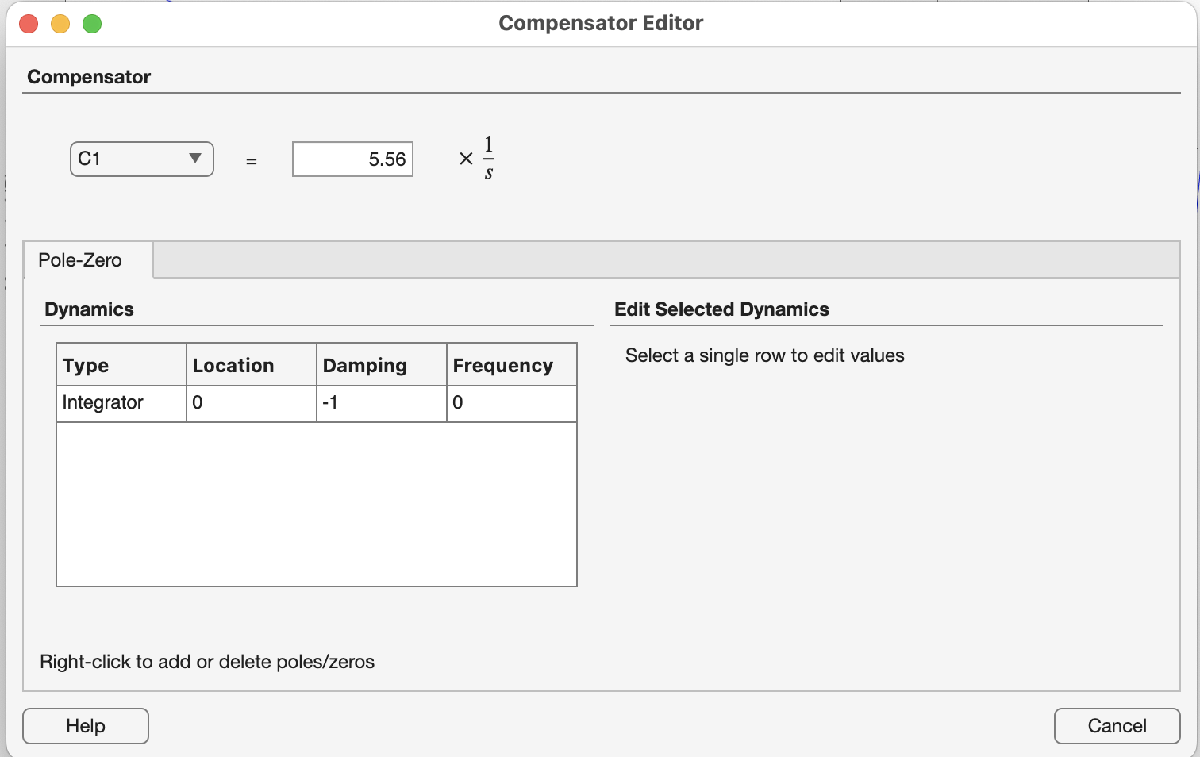

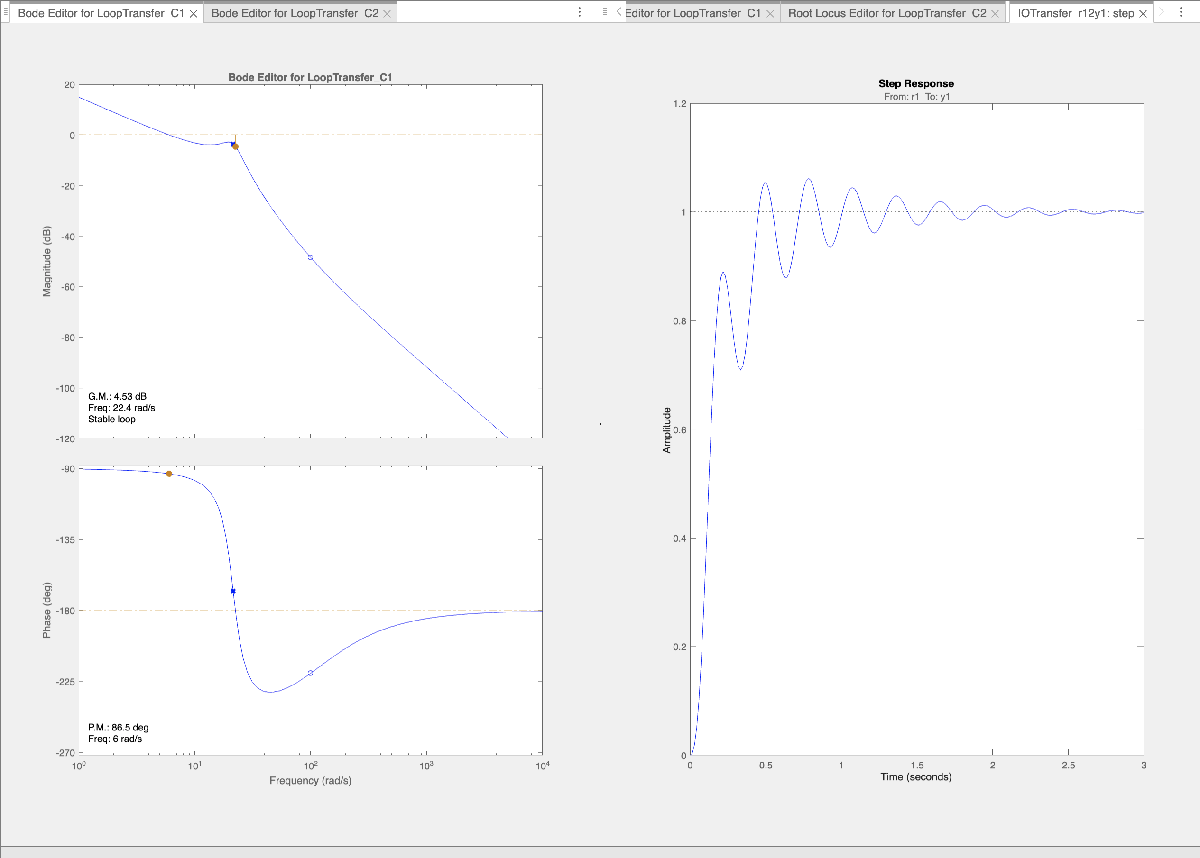

No need for further fine tuning. Note the oscillations in the closed loop step response, due to the complex poles of the transfer function $F_2(s)$, with natural frequency around $20 \;\text{rad/s}$.

ControlSystemDesigner session: `ControlSystemDesignerSessionC1.mat`